# Machine Learning: Programming Exercise 3

## Multi-class Classification and Neural Networks

In this exercise, you will implement one-vs-all logistic regression and neural networks to recognize hand-written digits.

## Files needed for this exercise

- `ex3.mlx` - MATLAB Live Script that steps you through the exercise

- `ex3.m, ex3_nn.m` - MATLAB scripts that step you through the exercise. (Not needed if using `ex3.mlx.)`

- `ex3data1.mat` - Training set of hand-written digits

- `ex3weights.mat` - Initial weights for the neural network exercise

- `submit.m `- Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `*lrCostFunction.m` - Logistic regression cost function

- `*oneVsAll.m` - Train a one-vs-all multi-class classifier

- `*predictOneVsAll.m` - Predict using a one-vs-all multi-class classifier

- `*predict.m `- Neural network prediction function

****indicates files you will need to complete***

## Setting up your environment

Run the commands below to clear your workspace of existing variables, remove other exercise folders from your search path, display your current directory, and list the files in your current directory. You should see all of the files above listed. If they are not, change you Current Folder to the **ex3** exercise folder.

To run the code inside of a MATLAB Live Script section:

- Click into the section to make it active. A blue bar will appear on the left.

- Click either the **Run Section (CTRL+ENTER)** or **Run and Advance (CTRL+SHIFT+ENTER) **buttons in the **Live Editor** tab above. Alternatively, you can click on the blue bar.

The **Run All** and **Run to End** are not recommended for use in these exercises. Executing the Live Script from the command line is also not recommended.

% Clear existing variables
clear;
% Remove existing exercises from search path, list current working directory, and list files in current directory
cleanPath();

ans = '/MATLAB Drive/Ng/machine-learning-ex3/ex3'


.                  displayData.m      ex3.mlx            ex3data1.mat       fmincg.m           lrCostFunction.m   predict.m          sigmoid.m          token.mat          
..                 ex3.m              ex3_nn.m           ex3weights.mat     lib                oneVsAll.m         predictOneVsAll.m  submit.m           



# 1. Multi-class Classification

For this exercise, you will use logistic regression and neural networks to recognize handwritten digits (from 0 to 9). Automated handwritten digit recognition is widely used today - from recognizing zip codes (postal codes) on mail envelopes to recognizing amounts written on bank checks. This exercise will show you how the methods you've learned can be used for this classication task. In the first part of the exercise, you will extend your previous implemention of logistic regression and apply it to one-vs-all classification.

## 1.1 Dataset

You are given a data set in `ex3data1.mat` that contains 5000 training examples of handwritten digits*. The .mat format means that that the data has been saved in a native MATLAB matrix format, instead of a text (ASCII) format like a csv-file. These matrices can be read directly into your program by using the load command. After loading, matrices of the correct dimensions and values will appear in your program's memory. The matrix will already be named, so you do not need to assign names to them. 

**This is a subset of the MNIST *[*handwritten digit dataset*](http://yann.lecun.com/exdb/mnist/))

Run the code below to load the data.

% Load saved matrices from file
load('ex3data1.mat');
% The matrices X and y will now be in your MATLAB environment

    There are 5000 training examples in `ex3data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


    The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '0', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

## 1.2 Visualizing the data

You will begin by visualizing a subset of the training set. The code below randomly selects selects 100 rows from `X` and passes those rows to the `displayData` function. This function maps each row to a 20 pixel by 20 pixel grayscale image and displays the images together. We have provided the `displayData` function, and you are encouraged to examine the code to see how it works. After you run this step, you should see an image like Figure 1.

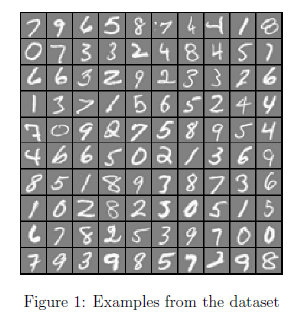                        

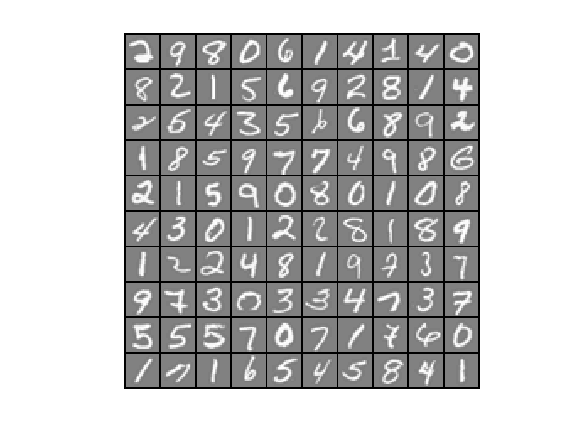

m = size(X, 1);
% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);

displayData(sel);

## 1.3 Vectorizing logistic regression

You will be using multiple one-vs-all logistic regression models to build a multi-class classifier. Since there are 10 classes, you will need to train 10 separate logistic regression classifiers. To make this training efficient, it is important to ensure that your code is well vectorized. In this section, you will implement a vectorized version of logistic regression that does not employ any `for` loops. You can use your code in the last exercise as a starting point for this exercise.

## 1.3.1 Vectorizing the cost function

We will begin by writing a vectorized version of the cost function. Recall that in (unregularized) logistic regression, the cost function is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1-y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


To compute each element in the summation, we have to compute $h_{\theta}(x^{(i)})$ for every example $i$, where $h_{\theta}(x^{(i)}) = g(\theta^T x^{(i)})$ and $g(z) =\frac{1}{1+e^{-z}}$ is the sigmoid function. It turns out that we can compute this quickly for all our examples by using matrix multiplication. Let us define $X$ and $\theta$ as


$$X\theta \text{ }=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T \theta \text{ }-\\
-{\left(x^{\left(2\right)} \right)}^T \theta \text{ }-\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T \theta \text{ }-
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\text{ }\theta^T \left(x^{\left(1\right)} \right)-\\
-{\text{ }\theta }^T \left(x^{\left(2\right)} \right)\text{ }-\\
\vdots \\
-{\text{ }\theta }^T \left(x^{\left(m\right)} \right)-
\end{array}\right\rbrack \text{ }$$


In the last equality, we used the fact that $a^T b= b^T a$ if $a$ and $b$ are vectors. This allows us to compute the products $\theta^T x^{(i)}$ for all our examples $i$ in one line of code.

    Your job is to write the unregularized cost function in the file `lrCostFunction.m `Your implementation should use the strategy we presented above to calculate $\theta^T x^{(i)}$. You should also use a vectorized approach for the rest of the cost function. A fully vectorized version of `lrCostFunction.m` should not contain any loops. (Hint: You might want to use the element-wise multiplication operation (`.*`) and the sum operation `sum` when writing this function)

## 1.3.2 Vectorizing the gradient

Recall that the gradient of the (unregularized) logistic regression cost is a vector where the $j$th element is defined as 


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}
$$


To vectorize this operation over the dataset, we start by writing out all the partial derivatives explicitly for all $\theta_j$,

$\left[ \begin{array}{c} 
\frac{\partial J(\theta)}{\partial \theta_0} \\
\frac{\partial J(\theta)}{\partial \theta_1} \\
\frac{\partial J(\theta)}{\partial \theta_2} \\
\vdots \\
\frac{\partial J(\theta)}{\partial \theta_n}   
 \end{array} \right]
 = \frac{1}{m}
\left[ \begin{array}{c} 
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_0^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_1^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_2^{(i)} \\
\vdots \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_n^{(i)}
\end{array}\right] =\frac{1}{m} \sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x^{(i)} =
\frac{1}{m}X^T {\left( h_\theta(x)-y\right)}
$   (1)

where


$$h_{\theta \text{ }} \left(x\right)-y=\left\lbrack \begin{array}{c}
h_{\theta \text{ }} \left(x^{\left(1\right)} \right)-y^{\left(1\right)} \\
h_{\theta \text{ }} \left(x^{\left(2\right)} \right)-y^{\left(2\right)} \\
\vdots \\
h_{\theta \text{ }} \left(x^{\left(m\right)} \right)-y^{\left(m\right)} 
\end{array}\right\rbrack$$


    Note that $x^{(i)}$ is a vector, while $(h_\theta(x^{(i)})-y^{(i)})$ is a scalar (single number). To understand the last step of the derivation, let $\beta_i = (h_\theta(x^{(i)})-y^{(i)})$ and observe that:


$$\sum_{i} \beta_i x^{\left(i\right)} =\left\lbrack \begin{array}{cccc}
| & | & \text{ } & |\\
x^{\left(1\right)}  & x^{\left(2\right)}  & \dots  & x^{\left(m\right)} \\
| & | & \text{ } & |
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\beta_1 \\
\beta_2 \\
\vdots \\
\beta_m 
\end{array}\right\rbrack =X^T \beta ,$$


    The expression above allows us to compute all the partial derivatives without any loops. If you are comfortable with linear algebra, we encourage you to work through the matrix multiplications above to convince yourself that the vectorized version does the same computations. You should now implement Equation (1) to compute the correct vectorized gradient. Once you are done, complete the function `lrCostFunction.m` by implementing the gradient.

**Debugging Tip: **Vectorizing code can sometimes be tricky. One common strategy for debugging is to print out the sizes of the matrices you are working with using the size function. For example, given a data matrix $X$ of size 100 x 20 (100 examples, 20 features) and $\theta$, a vector with dimensions 20 x 1, you can observe that $X\theta$ is a valid multiplication operation, while $\theta X$ is not. Furthermore, if you have a non-vectorized version of your code, you can compare the output of your vectorized code and non-vectorized code to make sure that they produce the same outputs.

## 1.3.3 Vectorizing regularized logistic regression

After you have implemented vectorization for logistic regression, you will now add regularization to the cost function. Recall that for regularized logistic regression, the cost function is defined as


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2}$$


Note that you should not be regularizing $\theta_0$ which is used for the bias term. Correspondingly, the partial derivative of regularized logistic regression cost for $\theta_j$ is defined as


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,
$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1$$


Now modify your code in `lrCostFunction` to account for regularization. Once again, you should not put any loops into your code. When you are finished, run the code below to test your vectorized implementation and compare to expected outputs:

theta_t = [-2; -1; 1; 2];
X_t = [ones(5,1) reshape(1:15,5,3)/10];
y_t = ([1;0;1;0;1] >= 0.5);

   0   0   1   0   0   0   0   0   0   0



lambda_t = 3;
[J, grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);

fprintf('Cost: %f | Expected cost: 2.534819\n',J);
fprintf('Gradients:\n'); fprintf('%f\n',grad);

h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h =     0.1089
    0.0953
    0.0646
    0.0667
    0.0641
    0.0814
    0.0570
    0.2528
    0.0479
    0.0870


Iteration     1 | Cost: 2.802128e-01


h =     0.0005
    0.0011
    0.0004
    0.0002
    0.0000
    0.0000
    0.0001
    0.0203
    0.0000
    0.0004


Iteration     2 | Cost: 9.454389e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1279
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0028
    0.0000
    0.0000


h =     0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0075
    0.0000
    0.0000


Iteration     3 | Cost: 5.704641e-02


h =     0.0010
    0.0017
    0.0001
    0.0000
    0.0000
    0.0000
    0.0001
    0.2138
    0.0000
    0.0006


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0020
    0.0000
    0.0000


Iteration     4 | Cost: 4.688190e-02


h =     0.0004
    0.0022
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2788
    0.0000
    0.0003


Iteration     5 | Cost: 3.759021e-02


h =     0.0010
    0.0231
    0.0002
    0.0000
    0.0000
    0.0000
    0.0004
    0.5425
    0.0000
    0.0019


h =     0.0003
    0.0022
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2009
    0.0000
    0.0003


Iteration     6 | Cost: 3.522008e-02


h =     0.0001
    0.0015
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2440
    0.0000
    0.0001


Iteration     7 | Cost: 3.234531e-02


h =     0.0001
    0.0011
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1581
    0.0000
    0.0000


h =     0.0001
    0.0013
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2140
    0.0000
    0.0001


Iteration     8 | Cost: 3.145034e-02


h =     0.0001
    0.0007
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1388
    0.0000
    0.0000


Iteration     9 | Cost: 3.008919e-02


h =     0.0000
    0.0004
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1094
    0.0000
    0.0000


h =     0.0001
    0.0006
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1339
    0.0000
    0.0000


Iteration    10 | Cost: 2.994639e-02


h =     0.0001
    0.0006
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1364
    0.0000
    0.0000


h =     0.0001
    0.0007
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1415
    0.0000
    0.0000


h =     0.0001
    0.0010
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1580
    0.0000
    0.0000


h =     0.0001
    0.0019
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1972
    0.0000
    0.0001


Iteration    11 | Cost: 2.678528e-02


h =     0.0002
    0.0020
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4783
    0.0000
    0.0000


h =     0.0001
    0.0015
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1712
    0.0000
    0.0001


h =     0.0001
    0.0016
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1806
    0.0000
    0.0001


Iteration    12 | Cost: 2.660323e-02


h =     0.0001
    0.0017
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1786
    0.0000
    0.0001


h =     0.0001
    0.0019
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1748
    0.0000
    0.0001


h =     0.0001
    0.0024
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1639
    0.0000
    0.0001


Iteration    13 | Cost: 2.493301e-02


h =     0.0002
    0.0052
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4482
    0.0000
    0.0001


h =     0.0001
    0.0020
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1417
    0.0000
    0.0001


Iteration    14 | Cost: 2.475211e-02


h =     0.0001
    0.0020
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1283
    0.0000
    0.0001


h =     0.0001
    0.0020
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1052
    0.0000
    0.0000


h =     0.0004
    0.0192
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.5813
    0.0000
    0.0003


Iteration    15 | Cost: 2.318421e-02


h =     0.0003
    0.0261
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.8696
    0.0000
    0.0002


h =     0.0002
    0.0128
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.3947
    0.0000
    0.0002


Iteration    16 | Cost: 2.287050e-02


h =     0.0002
    0.0110
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2944
    0.0000
    0.0001


h =     0.0001
    0.0080
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1638
    0.0000
    0.0001


Iteration    17 | Cost: 2.160258e-02


h =     0.0001
    0.0104
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2043
    0.0000
    0.0001


h =     0.0001
    0.0089
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1795
    0.0000
    0.0001


Iteration    18 | Cost: 2.120371e-02


h =     0.0001
    0.0062
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1560
    0.0000
    0.0001


Iteration    19 | Cost: 2.064125e-02


h =     0.0000
    0.0029
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1043
    0.0000
    0.0000


h =     0.0001
    0.0054
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1449
    0.0000
    0.0001


Iteration    20 | Cost: 2.055695e-02


h =     0.0001
    0.0054
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1448
    0.0000
    0.0001


Iteration    21 | Cost: 2.045466e-02


h =     0.0001
    0.0046
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1311
    0.0000
    0.0000


h =     0.0000
    0.0037
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1171
    0.0000
    0.0000


Iteration    22 | Cost: 2.029177e-02


h =     0.0004
    0.0280
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.9688
    0.0000
    0.0003


Iteration    23 | Cost: 2.005296e-02


h =     0.0000
    0.0036
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1077
    0.0000
    0.0000


h =     0.0000
    0.0033
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1030
    0.0000
    0.0000


Iteration    24 | Cost: 1.995949e-02


h =     0.0004
    0.0305
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.9718
    0.0000
    0.0003


Iteration    25 | Cost: 1.982849e-02


h =     0.0003
    0.0215
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.7976
    0.0000
    0.0002


Iteration    26 | Cost: 1.975129e-02


h =     0.0002
    0.0185
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.7174
    0.0000
    0.0002


h =     0.0002
    0.0136
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.5806
    0.0000
    0.0001


h =     0.0001
    0.0059
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.3275
    0.0000
    0.0000


Iteration    27 | Cost: 1.897815e-02


h =     0.0000
    0.0016
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.3598
    0.0000
    0.0000


h =     0.0000
    0.0034
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2325
    0.0000
    0.0000


Iteration    28 | Cost: 1.887065e-02


h =     0.0000
    0.0022
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1722
    0.0000
    0.0000


Iteration    29 | Cost: 1.869107e-02


h =     0.0000
    0.0036
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2268
    0.0000
    0.0000


h =     0.0000
    0.0028
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1963
    0.0000
    0.0000


Iteration    30 | Cost: 1.863223e-02


h =     0.0000
    0.0030
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2090
    0.0000
    0.0000


h =     0.0000
    0.0035
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2369
    0.0000
    0.0000


Iteration    31 | Cost: 1.837393e-02


h =     0.0000
    0.0049
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.3052
    0.0000
    0.0000


Iteration    32 | Cost: 1.816950e-02


h =     0.0000
    0.0051
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.3348
    0.0000
    0.0000


h =     0.0000
    0.0052
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.3682
    0.0000
    0.0000


Iteration    33 | Cost: 1.781689e-02


h =     0.0000
    0.0017
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1079
    0.0000
    0.0000


h =     0.0000
    0.0065
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4460
    0.0000
    0.0001


Iteration    34 | Cost: 1.774664e-02


h =     0.0000
    0.0064
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4439
    0.0000
    0.0001


Iteration    35 | Cost: 1.767442e-02


h =     0.0000
    0.0054
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4084
    0.0000
    0.0000


Iteration    36 | Cost: 1.758469e-02


h =     0.0000
    0.0046
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.3877
    0.0000
    0.0000


h =     0.0000
    0.0052
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4031
    0.0000
    0.0000


Iteration    37 | Cost: 1.756883e-02


h =     0.0000
    0.0054
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4133
    0.0000
    0.0000


h =     0.0000
    0.0056
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4256
    0.0000
    0.0000


Iteration    38 | Cost: 1.753420e-02


h =     0.0000
    0.0054
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4263
    0.0000
    0.0000


h =     0.0000
    0.0049
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4277
    0.0000
    0.0000


h =     0.0000
    0.0041
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4307
    0.0000
    0.0000


Iteration    39 | Cost: 1.728281e-02


h =     0.0000
    0.0035
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4891
    0.0000
    0.0000


Iteration    40 | Cost: 1.702065e-02


h =     0.0000
    0.0021
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4727
    0.0000
    0.0000


h =     0.0000
    0.0007
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4416
    0.0000
    0.0000


Iteration    41 | Cost: 1.621412e-02


h =     0.0000
    0.0002
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4337
    0.0000
    0.0000


Iteration    42 | Cost: 1.553730e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2882
    0.0000
    0.0000


Iteration    43 | Cost: 1.505034e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1671
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2262
    0.0000
    0.0000


Iteration    44 | Cost: 1.475035e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1854
    0.0000
    0.0000


Iteration    45 | Cost: 1.446390e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1899
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1877
    0.0000
    0.0000


Iteration    46 | Cost: 1.429809e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1926
    0.0000
    0.0000


Iteration    47 | Cost: 1.419130e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1501
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1775
    0.0000
    0.0000


Iteration    48 | Cost: 1.413422e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1671
    0.0000
    0.0000


Iteration    49 | Cost: 1.406843e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1647
    0.0000
    0.0000


Iteration    50 | Cost: 1.399210e-02


h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h =     0.1015
    0.0849
    0.0570
    0.0616
    0.0598
    0.0775
    0.0489
    0.2592
    0.0439
    0.0777


Iteration     1 | Cost: 3.448901e-01


h =     0.0246
    0.0071
    0.0149
    0.0696
    0.0027
    0.0140
    0.0007
    0.9509
    0.0034
    0.0053


Iteration     2 | Cost: 3.150694e-01


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.9189
    0.0000
    0.0000


Iteration     3 | Cost: 1.846843e-01


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.9990
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.9908
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.9722
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.9522
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.9375
    0.0000
    0.0000


Iteration     4 | Cost: 1.699017e-01


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.7851
    0.0000
    0.0000


Iteration     5 | Cost: 1.529566e-01


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.7433
    0.0000
    0.0000


Iteration     6 | Cost: 1.317377e-01


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4401
    0.0000
    0.0000


Iteration     7 | Cost: 1.171533e-01


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4283
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4331
    0.0000
    0.0000


Iteration     8 | Cost: 1.074286e-01


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.5330
    0.0000
    0.0000


Iteration     9 | Cost: 9.531806e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2810
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4564
    0.0000
    0.0000


Iteration    10 | Cost: 9.301912e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.4812
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.5308
    0.0000
    0.0000


Iteration    11 | Cost: 8.418356e-02


h =     0.0003
    0.0000
    0.0001
    0.0003
    0.0000
    0.0006
    0.0000
    0.8039
    0.0002
    0.0000


h =     0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000
    0.6132
    0.0000
    0.0000


Iteration    12 | Cost: 8.186322e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000
    0.5990
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000
    0.5823
    0.0000
    0.0000


Iteration    13 | Cost: 7.743126e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2463
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.5004
    0.0000
    0.0000


Iteration    14 | Cost: 7.645181e-02


h =     0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000
    0.4794
    0.0000
    0.0000


h =     0.0001
    0.0000
    0.0001
    0.0001
    0.0000
    0.0001
    0.0000
    0.4377
    0.0000
    0.0000


Iteration    15 | Cost: 7.209877e-02


h =     0.0012
    0.0001
    0.0008
    0.0014
    0.0000
    0.0028
    0.0000
    0.9283
    0.0011
    0.0001


h =     0.0001
    0.0000
    0.0001
    0.0001
    0.0000
    0.0001
    0.0000
    0.5076
    0.0001
    0.0000


h =     0.0001
    0.0000
    0.0001
    0.0001
    0.0000
    0.0001
    0.0000
    0.4703
    0.0001
    0.0000


Iteration    16 | Cost: 7.195896e-02


h =     0.0001
    0.0000
    0.0001
    0.0001
    0.0000
    0.0001
    0.0000
    0.4813
    0.0001
    0.0000


h =     0.0001
    0.0000
    0.0001
    0.0001
    0.0000
    0.0001
    0.0000
    0.5036
    0.0001
    0.0000


h =     0.0001
    0.0000
    0.0001
    0.0001
    0.0000
    0.0001
    0.0000
    0.5442
    0.0001
    0.0000


Iteration    17 | Cost: 7.106302e-02


h =     0.0004
    0.0000
    0.0002
    0.0004
    0.0000
    0.0005
    0.0000
    0.7159
    0.0002
    0.0000


h =     0.0002
    0.0000
    0.0001
    0.0002
    0.0000
    0.0002
    0.0000
    0.5902
    0.0001
    0.0000


Iteration    18 | Cost: 7.081516e-02


h =     0.0002
    0.0000
    0.0001
    0.0002
    0.0000
    0.0002
    0.0000
    0.5930
    0.0001
    0.0000


h =     0.0003
    0.0000
    0.0001
    0.0003
    0.0000
    0.0003
    0.0000
    0.5986
    0.0001
    0.0000


Iteration    19 | Cost: 6.984782e-02


h =     0.0003
    0.0000
    0.0001
    0.0002
    0.0000
    0.0002
    0.0000
    0.5053
    0.0001
    0.0000


Iteration    20 | Cost: 6.908892e-02


h =     0.0004
    0.0000
    0.0002
    0.0003
    0.0000
    0.0002
    0.0000
    0.4564
    0.0001
    0.0000


Iteration    21 | Cost: 6.818820e-02


h =     0.0007
    0.0000
    0.0003
    0.0007
    0.0000
    0.0007
    0.0000
    0.6456
    0.0004
    0.0000


h =     0.0004
    0.0000
    0.0002
    0.0004
    0.0000
    0.0003
    0.0000
    0.4947
    0.0002
    0.0000


Iteration    22 | Cost: 6.804182e-02


h =     0.0004
    0.0000
    0.0002
    0.0004
    0.0000
    0.0003
    0.0000
    0.5115
    0.0002
    0.0000


Iteration    23 | Cost: 6.788125e-02


h =     0.0005
    0.0000
    0.0002
    0.0005
    0.0000
    0.0004
    0.0000
    0.5637
    0.0002
    0.0000


h =     0.0005
    0.0000
    0.0002
    0.0004
    0.0000
    0.0004
    0.0000
    0.5444
    0.0002
    0.0000


Iteration    24 | Cost: 6.779397e-02


h =     0.0005
    0.0000
    0.0002
    0.0005
    0.0000
    0.0004
    0.0000
    0.5664
    0.0002
    0.0000


Iteration    25 | Cost: 6.767277e-02


h =     0.0005
    0.0000
    0.0002
    0.0004
    0.0000
    0.0003
    0.0000
    0.5397
    0.0002
    0.0000


Iteration    26 | Cost: 6.760372e-02


h =     0.0004
    0.0000
    0.0002
    0.0004
    0.0000
    0.0003
    0.0000
    0.5227
    0.0002
    0.0000


h =     0.0004
    0.0000
    0.0002
    0.0004
    0.0000
    0.0002
    0.0000
    0.5012
    0.0001
    0.0000


Iteration    27 | Cost: 6.740638e-02


h =     0.0005
    0.0000
    0.0003
    0.0005
    0.0000
    0.0003
    0.0000
    0.5404
    0.0002
    0.0000


h =     0.0005
    0.0000
    0.0002
    0.0004
    0.0000
    0.0003
    0.0000
    0.5189
    0.0002
    0.0000


Iteration    28 | Cost: 6.731728e-02


h =     0.0005
    0.0000
    0.0002
    0.0005
    0.0000
    0.0003
    0.0000
    0.5277
    0.0002
    0.0000


h =     0.0005
    0.0000
    0.0002
    0.0005
    0.0000
    0.0004
    0.0000
    0.5453
    0.0002
    0.0000


Iteration    29 | Cost: 6.698888e-02


h =     0.0004
    0.0000
    0.0001
    0.0003
    0.0000
    0.0002
    0.0000
    0.4853
    0.0001
    0.0000


h =     0.0005
    0.0000
    0.0002
    0.0005
    0.0000
    0.0003
    0.0000
    0.5315
    0.0002
    0.0000


Iteration    30 | Cost: 6.692984e-02


h =     0.0005
    0.0000
    0.0002
    0.0005
    0.0000
    0.0003
    0.0000
    0.5286
    0.0002
    0.0000


h =     0.0005
    0.0000
    0.0002
    0.0005
    0.0000
    0.0003
    0.0000
    0.5228
    0.0002
    0.0000


h =     0.0005
    0.0000
    0.0002
    0.0005
    0.0000
    0.0002
    0.0000
    0.5052
    0.0002
    0.0000


Iteration    31 | Cost: 6.630404e-02


h =     0.0007
    0.0001
    0.0004
    0.0008
    0.0000
    0.0004
    0.0000
    0.5627
    0.0003
    0.0000


h =     0.0006
    0.0000
    0.0003
    0.0006
    0.0000
    0.0003
    0.0000
    0.5295
    0.0002
    0.0000


Iteration    32 | Cost: 6.606809e-02


h =     0.0006
    0.0000
    0.0003
    0.0006
    0.0000
    0.0003
    0.0000
    0.5382
    0.0002
    0.0000


h =     0.0007
    0.0001
    0.0003
    0.0008
    0.0000
    0.0004
    0.0000
    0.5553
    0.0003
    0.0000


h =     0.0010
    0.0001
    0.0004
    0.0011
    0.0000
    0.0006
    0.0000
    0.5812
    0.0005
    0.0000


Iteration    33 | Cost: 6.466816e-02


h =     0.0006
    0.0000
    0.0002
    0.0005
    0.0000
    0.0003
    0.0000
    0.4818
    0.0002
    0.0000


h =     0.0008
    0.0001
    0.0003
    0.0009
    0.0000
    0.0005
    0.0000
    0.5515
    0.0004
    0.0000


Iteration    34 | Cost: 6.426962e-02


h =     0.0008
    0.0001
    0.0003
    0.0008
    0.0000
    0.0004
    0.0000
    0.5263
    0.0003
    0.0000


h =     0.0007
    0.0001
    0.0003
    0.0008
    0.0000
    0.0003
    0.0000
    0.4755
    0.0003
    0.0000


Iteration    35 | Cost: 6.267791e-02


h =     0.0019
    0.0002
    0.0014
    0.0031
    0.0000
    0.0007
    0.0000
    0.6166
    0.0013
    0.0000


h =     0.0008
    0.0001
    0.0004
    0.0009
    0.0000
    0.0003
    0.0000
    0.4923
    0.0004
    0.0000


Iteration    36 | Cost: 6.251576e-02


h =     0.0008
    0.0001
    0.0004
    0.0010
    0.0000
    0.0003
    0.0000
    0.5094
    0.0004
    0.0000


h =     0.0010
    0.0001
    0.0004
    0.0011
    0.0000
    0.0004
    0.0000
    0.5435
    0.0005
    0.0000


Iteration    37 | Cost: 6.202834e-02


h =     0.0007
    0.0000
    0.0002
    0.0007
    0.0000
    0.0003
    0.0000
    0.5094
    0.0003
    0.0000


h =     0.0008
    0.0001
    0.0004
    0.0009
    0.0000
    0.0004
    0.0000
    0.5321
    0.0004
    0.0000


Iteration    38 | Cost: 6.188522e-02


h =     0.0008
    0.0001
    0.0003
    0.0008
    0.0000
    0.0004
    0.0000
    0.5273
    0.0004
    0.0000


h =     0.0007
    0.0001
    0.0003
    0.0007
    0.0000
    0.0003
    0.0000
    0.5178
    0.0003
    0.0000


h =     0.0004
    0.0000
    0.0002
    0.0004
    0.0000
    0.0002
    0.0000
    0.4893
    0.0002
    0.0000


Iteration    39 | Cost: 6.013896e-02


h =     0.0005
    0.0000
    0.0003
    0.0006
    0.0000
    0.0003
    0.0000
    0.5441
    0.0003
    0.0000


Iteration    40 | Cost: 5.937078e-02


h =     0.0002
    0.0000
    0.0001
    0.0002
    0.0000
    0.0001
    0.0000
    0.4370
    0.0001
    0.0000


h =     0.0004
    0.0000
    0.0002
    0.0004
    0.0000
    0.0002
    0.0000
    0.5039
    0.0002
    0.0000


Iteration    41 | Cost: 5.888593e-02


h =     0.0004
    0.0000
    0.0003
    0.0005
    0.0000
    0.0002
    0.0000
    0.4616
    0.0003
    0.0000


h =     0.0004
    0.0000
    0.0002
    0.0004
    0.0000
    0.0002
    0.0000
    0.4822
    0.0003
    0.0000


Iteration    42 | Cost: 5.862828e-02


h =     0.0004
    0.0000
    0.0004
    0.0007
    0.0000
    0.0002
    0.0000
    0.4704
    0.0003
    0.0000


h =     0.0004
    0.0000
    0.0003
    0.0005
    0.0000
    0.0002
    0.0000
    0.4786
    0.0003
    0.0000


Iteration    43 | Cost: 5.854428e-02


h =     0.0003
    0.0000
    0.0003
    0.0005
    0.0000
    0.0002
    0.0000
    0.4556
    0.0002
    0.0000


Iteration    44 | Cost: 5.847598e-02


h =     0.0004
    0.0000
    0.0003
    0.0006
    0.0000
    0.0002
    0.0000
    0.4575
    0.0003
    0.0000


Iteration    45 | Cost: 5.840091e-02


h =     0.0004
    0.0000
    0.0003
    0.0006
    0.0000
    0.0002
    0.0000
    0.4665
    0.0003
    0.0000


h =     0.0004
    0.0000
    0.0004
    0.0006
    0.0000
    0.0002
    0.0000
    0.4846
    0.0003
    0.0000


Iteration    46 | Cost: 5.812346e-02


h =     0.0006
    0.0000
    0.0006
    0.0009
    0.0000
    0.0004
    0.0000
    0.5545
    0.0006
    0.0000


h =     0.0004
    0.0000
    0.0004
    0.0007
    0.0000
    0.0003
    0.0000
    0.5105
    0.0004
    0.0000


Iteration    47 | Cost: 5.803256e-02


h =     0.0005
    0.0000
    0.0004
    0.0007
    0.0000
    0.0003
    0.0000
    0.5247
    0.0004
    0.0000


h =     0.0005
    0.0000
    0.0004
    0.0007
    0.0000
    0.0004
    0.0000
    0.5529
    0.0004
    0.0000


Iteration    48 | Cost: 5.773512e-02


h =     0.0003
    0.0000
    0.0003
    0.0004
    0.0000
    0.0003
    0.0000
    0.5039
    0.0002
    0.0000


h =     0.0004
    0.0000
    0.0003
    0.0006
    0.0000
    0.0004
    0.0000
    0.5334
    0.0003
    0.0000


Iteration    49 | Cost: 5.763074e-02


h =     0.0004
    0.0000
    0.0003
    0.0005
    0.0000
    0.0004
    0.0000
    0.5219
    0.0003
    0.0000


h =     0.0004
    0.0000
    0.0003
    0.0005
    0.0000
    0.0003
    0.0000
    0.4989
    0.0002
    0.0000


Iteration    50 | Cost: 5.725252e-02


h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h =     0.1041
    0.0890
    0.0590
    0.0609
    0.0659
    0.0773
    0.0551
    0.2576
    0.0486
    0.0882


Iteration     1 | Cost: 3.456557e-01


h =     0.1306
    0.1622
    0.1337
    0.0419
    0.5874
    0.0127
    0.6222
    0.8894
    0.6874
    0.9574


h =     0.1157
    0.1183
    0.0869
    0.0513
    0.2210
    0.0340
    0.2151
    0.5981
    0.2258
    0.5469


Iteration     2 | Cost: 2.179164e-01


h =     0.0011
    0.0009
    0.0004
    0.0001
    0.0016
    0.0001
    0.0016
    0.2136
    0.0013
    0.0395


Iteration     3 | Cost: 1.784174e-01


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1468
    0.0000
    0.6645


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1778
    0.0000
    0.2220


h =     0.0001
    0.0000
    0.0000
    0.0000
    0.0002
    0.0000
    0.0004
    0.2000
    0.0003
    0.0767


Iteration     4 | Cost: 1.678808e-01


h =     0.0014
    0.0015
    0.0031
    0.0004
    0.0041
    0.0000
    0.0213
    0.3338
    0.0096
    0.5372


h =     0.0005
    0.0005
    0.0008
    0.0001
    0.0016
    0.0000
    0.0066
    0.2891
    0.0033
    0.3448


Iteration     5 | Cost: 1.427129e-01


h =     0.0012
    0.0014
    0.0038
    0.0006
    0.0018
    0.0000
    0.0162
    0.1564
    0.0041
    0.3468


Iteration     6 | Cost: 1.150393e-01


h =     0.0002
    0.0002
    0.0003
    0.0001
    0.0002
    0.0000
    0.0013
    0.0468
    0.0002
    0.0484


h =     0.0005
    0.0006
    0.0014
    0.0002
    0.0007
    0.0000
    0.0057
    0.0958
    0.0012
    0.1653


Iteration     7 | Cost: 1.063718e-01


h =     0.0007
    0.0010
    0.0020
    0.0005
    0.0019
    0.0000
    0.0169
    0.0687
    0.0032
    0.2587


Iteration     8 | Cost: 9.707803e-02


h =     0.0072
    0.0225
    0.0247
    0.0101
    0.0426
    0.0002
    0.4215
    0.1746
    0.0939
    0.8987


h =     0.0010
    0.0018
    0.0032
    0.0009
    0.0034
    0.0000
    0.0334
    0.0823
    0.0061
    0.3896


Iteration     9 | Cost: 9.518367e-02


h =     0.0010
    0.0020
    0.0029
    0.0009
    0.0034
    0.0000
    0.0362
    0.0781
    0.0061
    0.4060


h =     0.0011
    0.0024
    0.0023
    0.0009
    0.0035
    0.0000
    0.0424
    0.0703
    0.0059
    0.4394


Iteration    10 | Cost: 9.035733e-02


h =     0.0047
    0.0207
    0.0109
    0.0053
    0.0229
    0.0001
    0.4360
    0.0870
    0.0591
    0.8940


h =     0.0014
    0.0037
    0.0032
    0.0013
    0.0051
    0.0000
    0.0724
    0.0734
    0.0094
    0.5565


Iteration    11 | Cost: 8.928846e-02


h =     0.0012
    0.0034
    0.0027
    0.0010
    0.0042
    0.0000
    0.0737
    0.0572
    0.0086
    0.5463


h =     0.0009
    0.0027
    0.0020
    0.0007
    0.0029
    0.0000
    0.0762
    0.0344
    0.0072
    0.5258


Iteration    12 | Cost: 8.531186e-02


h =     0.0010
    0.0036
    0.0033
    0.0009
    0.0040
    0.0000
    0.1633
    0.0251
    0.0148
    0.6671


h =     0.0009
    0.0032
    0.0028
    0.0008
    0.0036
    0.0000
    0.1250
    0.0281
    0.0114
    0.6179


Iteration    13 | Cost: 8.333526e-02


h =     0.0005
    0.0021
    0.0022
    0.0004
    0.0023
    0.0000
    0.1286
    0.0138
    0.0101
    0.5828


Iteration    14 | Cost: 8.052683e-02


h =     0.0003
    0.0011
    0.0010
    0.0002
    0.0011
    0.0000
    0.0651
    0.0094
    0.0046
    0.4180


h =     0.0004
    0.0014
    0.0014
    0.0003
    0.0015
    0.0000
    0.0849
    0.0109
    0.0062
    0.4807


Iteration    15 | Cost: 7.932857e-02


h =     0.0003
    0.0010
    0.0013
    0.0002
    0.0014
    0.0000
    0.0736
    0.0096
    0.0062
    0.4591


h =     0.0003
    0.0008
    0.0012
    0.0002
    0.0013
    0.0000
    0.0623
    0.0084
    0.0062
    0.4343


Iteration    16 | Cost: 7.672637e-02


h =     0.0002
    0.0006
    0.0014
    0.0003
    0.0005
    0.0000
    0.0281
    0.0130
    0.0039
    0.4063


Iteration    17 | Cost: 7.530942e-02


h =     0.0000
    0.0001
    0.0002
    0.0000
    0.0000
    0.0000
    0.0007
    0.0093
    0.0001
    0.0681


h =     0.0002
    0.0004
    0.0011
    0.0002
    0.0003
    0.0000
    0.0167
    0.0124
    0.0024
    0.3310


Iteration    18 | Cost: 7.500108e-02


h =     0.0001
    0.0004
    0.0009
    0.0002
    0.0003
    0.0000
    0.0169
    0.0107
    0.0022
    0.3110


Iteration    19 | Cost: 7.445295e-02


h =     0.0002
    0.0004
    0.0011
    0.0002
    0.0004
    0.0000
    0.0225
    0.0099
    0.0028
    0.3433


Iteration    20 | Cost: 7.391453e-02


h =     0.0001
    0.0003
    0.0009
    0.0001
    0.0003
    0.0000
    0.0209
    0.0080
    0.0023
    0.3060


Iteration    21 | Cost: 7.349869e-02


h =     0.0001
    0.0004
    0.0010
    0.0001
    0.0004
    0.0000
    0.0300
    0.0064
    0.0028
    0.3318


Iteration    22 | Cost: 7.307295e-02


h =     0.0002
    0.0006
    0.0019
    0.0003
    0.0007
    0.0000
    0.0534
    0.0085
    0.0050
    0.4663


h =     0.0002
    0.0004
    0.0012
    0.0002
    0.0005
    0.0000
    0.0350
    0.0069
    0.0033
    0.3659


Iteration    23 | Cost: 7.296937e-02


h =     0.0002
    0.0004
    0.0012
    0.0002
    0.0005
    0.0000
    0.0358
    0.0070
    0.0032
    0.3730


h =     0.0002
    0.0005
    0.0013
    0.0002
    0.0005
    0.0000
    0.0374
    0.0072
    0.0032
    0.3873


Iteration    24 | Cost: 7.262398e-02


h =     0.0002
    0.0005
    0.0014
    0.0002
    0.0005
    0.0000
    0.0417
    0.0064
    0.0034
    0.3895


h =     0.0002
    0.0005
    0.0015
    0.0002
    0.0005
    0.0000
    0.0519
    0.0050
    0.0039
    0.3938


Iteration    25 | Cost: 7.129794e-02


h =     0.0001
    0.0002
    0.0006
    0.0001
    0.0002
    0.0000
    0.0252
    0.0024
    0.0015
    0.2335


h =     0.0002
    0.0004
    0.0014
    0.0002
    0.0005
    0.0000
    0.0472
    0.0046
    0.0034
    0.3700


Iteration    26 | Cost: 7.118480e-02


h =     0.0002
    0.0004
    0.0013
    0.0002
    0.0004
    0.0000
    0.0477
    0.0041
    0.0033
    0.3679


h =     0.0002
    0.0004
    0.0013
    0.0002
    0.0004
    0.0000
    0.0485
    0.0036
    0.0032
    0.3649


Iteration    27 | Cost: 7.089717e-02


h =     0.0002
    0.0004
    0.0015
    0.0002
    0.0005
    0.0000
    0.0579
    0.0034
    0.0037
    0.3972


h =     0.0002
    0.0005
    0.0019
    0.0003
    0.0006
    0.0000
    0.0818
    0.0030
    0.0049
    0.4642


Iteration    28 | Cost: 6.963444e-02


h =     0.0003
    0.0008
    0.0040
    0.0004
    0.0008
    0.0000
    0.0925
    0.0113
    0.0091
    0.5265


h =     0.0002
    0.0005
    0.0020
    0.0003
    0.0006
    0.0000
    0.0829
    0.0034
    0.0052
    0.4704


h =     0.0002
    0.0005
    0.0019
    0.0003
    0.0006
    0.0000
    0.0823
    0.0031
    0.0050
    0.4668


Iteration    29 | Cost: 6.959800e-02


h =     0.0002
    0.0005
    0.0019
    0.0003
    0.0006
    0.0000
    0.0816
    0.0031
    0.0050
    0.4636


h =     0.0002
    0.0005
    0.0019
    0.0003
    0.0005
    0.0000
    0.0802
    0.0031
    0.0049
    0.4574


h =     0.0002
    0.0004
    0.0019
    0.0003
    0.0005
    0.0000
    0.0763
    0.0030
    0.0045
    0.4388


Iteration    30 | Cost: 6.916224e-02


h =     0.0001
    0.0003
    0.0013
    0.0002
    0.0003
    0.0000
    0.0503
    0.0025
    0.0028
    0.3386


Iteration    31 | Cost: 6.893772e-02


h =     0.0000
    0.0000
    0.0002
    0.0000
    0.0000
    0.0000
    0.0074
    0.0011
    0.0003
    0.0674


h =     0.0001
    0.0002
    0.0011
    0.0002
    0.0002
    0.0000
    0.0417
    0.0023
    0.0022
    0.2962


h =     0.0001
    0.0002
    0.0011
    0.0002
    0.0002
    0.0000
    0.0451
    0.0024
    0.0024
    0.3137


Iteration    32 | Cost: 6.891904e-02


h =     0.0001
    0.0002
    0.0011
    0.0002
    0.0002
    0.0000
    0.0458
    0.0024
    0.0025
    0.3164


h =     0.0001
    0.0002
    0.0012
    0.0002
    0.0002
    0.0000
    0.0471
    0.0024
    0.0025
    0.3218


h =     0.0001
    0.0003
    0.0013
    0.0002
    0.0002
    0.0000
    0.0513
    0.0025
    0.0028
    0.3384


Iteration    33 | Cost: 6.872523e-02


h =     0.0002
    0.0003
    0.0014
    0.0002
    0.0003
    0.0000
    0.0628
    0.0027
    0.0033
    0.3873


Iteration    34 | Cost: 6.853461e-02


h =     0.0001
    0.0002
    0.0009
    0.0002
    0.0002
    0.0000
    0.0474
    0.0022
    0.0021
    0.3191


h =     0.0002
    0.0003
    0.0013
    0.0002
    0.0003
    0.0000
    0.0585
    0.0026
    0.0030
    0.3695


Iteration    35 | Cost: 6.849292e-02


h =     0.0002
    0.0003
    0.0012
    0.0002
    0.0003
    0.0000
    0.0589
    0.0025
    0.0028
    0.3676


h =     0.0001
    0.0003
    0.0012
    0.0002
    0.0003
    0.0000
    0.0596
    0.0024
    0.0026
    0.3639


h =     0.0001
    0.0002
    0.0010
    0.0002
    0.0003
    0.0000
    0.0617
    0.0021
    0.0021
    0.3529


h =     0.0001
    0.0002
    0.0007
    0.0001
    0.0003
    0.0000
    0.0670
    0.0015
    0.0012
    0.3275


Iteration    36 | Cost: 6.755014e-02


h =     0.0001
    0.0002
    0.0010
    0.0002
    0.0005
    0.0000
    0.1409
    0.0015
    0.0016
    0.4522


h =     0.0001
    0.0002
    0.0008
    0.0001
    0.0003
    0.0000
    0.0902
    0.0015
    0.0013
    0.3745


Iteration    37 | Cost: 6.715962e-02


h =     0.0001
    0.0002
    0.0007
    0.0001
    0.0003
    0.0000
    0.0862
    0.0015
    0.0012
    0.3548


h =     0.0001
    0.0001
    0.0004
    0.0001
    0.0002
    0.0000
    0.0787
    0.0015
    0.0010
    0.3168


Iteration    38 | Cost: 6.583924e-02


h =     0.0000
    0.0000
    0.0001
    0.0000
    0.0000
    0.0000
    0.0118
    0.0005
    0.0001
    0.0728


h =     0.0001
    0.0001
    0.0004
    0.0001
    0.0002
    0.0000
    0.0656
    0.0013
    0.0008
    0.2797


Iteration    39 | Cost: 6.575350e-02


h =     0.0000
    0.0001
    0.0003
    0.0001
    0.0001
    0.0000
    0.0572
    0.0011
    0.0007
    0.2532


Iteration    40 | Cost: 6.559090e-02


h =     0.0000
    0.0001
    0.0004
    0.0001
    0.0001
    0.0000
    0.0611
    0.0012
    0.0008
    0.2647


h =     0.0000
    0.0001
    0.0005
    0.0001
    0.0001
    0.0000
    0.0697
    0.0012
    0.0009
    0.2887


Iteration    41 | Cost: 6.518378e-02


h =     0.0000
    0.0001
    0.0005
    0.0001
    0.0001
    0.0000
    0.0680
    0.0008
    0.0010
    0.2849


Iteration    42 | Cost: 6.469875e-02


h =     0.0001
    0.0001
    0.0012
    0.0001
    0.0002
    0.0000
    0.1189
    0.0008
    0.0024
    0.4106


h =     0.0001
    0.0001
    0.0007
    0.0001
    0.0001
    0.0000
    0.0792
    0.0008
    0.0013
    0.3163


Iteration    43 | Cost: 6.460153e-02


h =     0.0001
    0.0001
    0.0008
    0.0001
    0.0001
    0.0000
    0.0918
    0.0008
    0.0017
    0.3507


Iteration    44 | Cost: 6.450477e-02


h =     0.0001
    0.0001
    0.0008
    0.0001
    0.0001
    0.0000
    0.0891
    0.0007
    0.0018
    0.3458


h =     0.0001
    0.0001
    0.0008
    0.0001
    0.0001
    0.0000
    0.0857
    0.0006
    0.0019
    0.3396


Iteration    45 | Cost: 6.429370e-02


h =     0.0001
    0.0001
    0.0007
    0.0001
    0.0001
    0.0000
    0.0803
    0.0007
    0.0019
    0.3303


Iteration    46 | Cost: 6.403671e-02


h =     0.0001
    0.0001
    0.0008
    0.0001
    0.0001
    0.0000
    0.0881
    0.0007
    0.0016
    0.3473


Iteration    47 | Cost: 6.384263e-02


h =     0.0000
    0.0001
    0.0006
    0.0001
    0.0001
    0.0000
    0.0742
    0.0006
    0.0009
    0.3079


Iteration    48 | Cost: 6.371185e-02


h =     0.0000
    0.0001
    0.0005
    0.0001
    0.0001
    0.0000
    0.0678
    0.0006
    0.0009
    0.2924


Iteration    49 | Cost: 6.351967e-02


h =     0.0000
    0.0001
    0.0005
    0.0001
    0.0001
    0.0000
    0.0825
    0.0007
    0.0011
    0.3350


Iteration    50 | Cost: 6.330618e-02


h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h =     0.1014
    0.0864
    0.0582
    0.0619
    0.0633
    0.0800
    0.0525
    0.2398
    0.0461
    0.0794


Iteration     1 | Cost: 3.205301e-01


h =     0.0008
    0.0006
    0.0008
    0.0016
    0.0016
    0.0024
    0.0009
    0.0045
    0.0008
    0.0005


Iteration     2 | Cost: 3.040759e-01


h =     0.0002
    0.0001
    0.0000
    0.0001
    0.0001
    0.0003
    0.0000
    0.1070
    0.0000
    0.0001


Iteration     3 | Cost: 1.649080e-01


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.8841
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.3075
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0002
    0.0000
    0.0000
    0.0000
    0.5735
    0.0000
    0.0000


h =     0.0001
    0.0000
    0.0000
    0.0002
    0.0000
    0.0001
    0.0000
    0.2747
    0.0000
    0.0000


Iteration     4 | Cost: 1.438784e-01


h =     0.0005
    0.0004
    0.0022
    0.0056
    0.0000
    0.0000
    0.0002
    0.4441
    0.0000
    0.0004


Iteration     5 | Cost: 9.416994e-02


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1618
    0.0000
    0.0000


h =     0.0002
    0.0002
    0.0010
    0.0025
    0.0000
    0.0000
    0.0001
    0.3973
    0.0000
    0.0002


Iteration     6 | Cost: 9.044270e-02


h =     0.0002
    0.0002
    0.0015
    0.0031
    0.0000
    0.0000
    0.0001
    0.5909
    0.0000
    0.0003


h =     0.0000
    0.0000
    0.0003
    0.0005
    0.0000
    0.0000
    0.0000
    0.1307
    0.0000
    0.0001


Iteration     7 | Cost: 7.499076e-02


h =     0.0005
    0.0007
    0.0243
    0.0292
    0.0000
    0.0000
    0.0011
    0.6908
    0.0002
    0.0021


h =     0.0000
    0.0000
    0.0008
    0.0011
    0.0000
    0.0000
    0.0000
    0.1820
    0.0000
    0.0001


Iteration     8 | Cost: 7.202465e-02


h =     0.0001
    0.0001
    0.0016
    0.0020
    0.0000
    0.0000
    0.0001
    0.3345
    0.0000
    0.0003


h =     0.0001
    0.0001
    0.0008
    0.0007
    0.0000
    0.0000
    0.0000
    0.1130
    0.0000
    0.0001


Iteration     9 | Cost: 6.313221e-02


h =     0.0002
    0.0001
    0.0014
    0.0005
    0.0000
    0.0000
    0.0000
    0.1826
    0.0000
    0.0003


h =     0.0001
    0.0001
    0.0008
    0.0006
    0.0000
    0.0000
    0.0000
    0.1231
    0.0000
    0.0001


Iteration    10 | Cost: 6.168143e-02


h =     0.0002
    0.0002
    0.0019
    0.0012
    0.0000
    0.0000
    0.0000
    0.1677
    0.0000
    0.0003


h =     0.0007
    0.0005
    0.0083
    0.0036
    0.0000
    0.0000
    0.0001
    0.2900
    0.0000
    0.0011


Iteration    11 | Cost: 5.762801e-02


h =     0.0002
    0.0002
    0.0030
    0.0014
    0.0000
    0.0000
    0.0001
    0.1314
    0.0001
    0.0007


h =     0.0010
    0.0008
    0.0123
    0.0054
    0.0001
    0.0000
    0.0001
    0.4561
    0.0001
    0.0020


Iteration    12 | Cost: 5.638036e-02


h =     0.0008
    0.0007
    0.0087
    0.0041
    0.0001
    0.0000
    0.0001
    0.5582
    0.0001
    0.0019


Iteration    13 | Cost: 5.517793e-02


h =     0.0015
    0.0014
    0.0161
    0.0092
    0.0002
    0.0001
    0.0003
    0.6669
    0.0003
    0.0046


Iteration    14 | Cost: 5.405985e-02


h =     0.0020
    0.0021
    0.0173
    0.0128
    0.0003
    0.0001
    0.0004
    0.5955
    0.0005
    0.0080


Iteration    15 | Cost: 5.332997e-02


h =     0.0039
    0.0039
    0.0304
    0.0258
    0.0006
    0.0001
    0.0007
    0.3763
    0.0009
    0.0171


Iteration    16 | Cost: 5.177817e-02


h =     0.0040
    0.0035
    0.0273
    0.0227
    0.0006
    0.0001
    0.0005
    0.2667
    0.0008
    0.0150


Iteration    17 | Cost: 5.019780e-02


h =     0.0127
    0.0108
    0.1289
    0.1074
    0.0020
    0.0003
    0.0022
    0.3170
    0.0037
    0.0508


h =     0.0045
    0.0039
    0.0319
    0.0265
    0.0007
    0.0001
    0.0006
    0.2713
    0.0009
    0.0169


Iteration    18 | Cost: 5.009061e-02


h =     0.0046
    0.0039
    0.0323
    0.0272
    0.0006
    0.0001
    0.0006
    0.2552
    0.0009
    0.0169


h =     0.0048
    0.0039
    0.0332
    0.0285
    0.0006
    0.0001
    0.0006
    0.2257
    0.0009
    0.0169


h =     0.0052
    0.0038
    0.0349
    0.0312
    0.0006
    0.0001
    0.0005
    0.1799
    0.0008
    0.0169


Iteration    19 | Cost: 4.933097e-02


h =     0.0032
    0.0020
    0.0171
    0.0164
    0.0002
    0.0000
    0.0002
    0.1150
    0.0003
    0.0090


h =     0.0044
    0.0030
    0.0269
    0.0247
    0.0004
    0.0001
    0.0004
    0.1530
    0.0006
    0.0134


Iteration    20 | Cost: 4.906466e-02


h =     0.0037
    0.0025
    0.0232
    0.0223
    0.0003
    0.0000
    0.0003
    0.1381
    0.0005
    0.0115


h =     0.0026
    0.0017
    0.0172
    0.0182
    0.0002
    0.0000
    0.0002
    0.1126
    0.0004
    0.0084


Iteration    21 | Cost: 4.795494e-02


h =     0.0072
    0.0047
    0.0741
    0.0733
    0.0004
    0.0001
    0.0008
    0.1454
    0.0013
    0.0229


h =     0.0029
    0.0018
    0.0199
    0.0209
    0.0002
    0.0000
    0.0002
    0.1155
    0.0004
    0.0093


Iteration    22 | Cost: 4.787525e-02


h =     0.0030
    0.0019
    0.0207
    0.0216
    0.0002
    0.0000
    0.0002
    0.1135
    0.0004
    0.0093


h =     0.0032
    0.0020
    0.0225
    0.0231
    0.0002
    0.0000
    0.0002
    0.1096
    0.0004
    0.0094


h =     0.0035
    0.0021
    0.0255
    0.0257
    0.0002
    0.0000
    0.0003
    0.1037
    0.0004
    0.0095


Iteration    23 | Cost: 4.736362e-02


h =     0.0284
    0.0162
    0.1791
    0.1803
    0.0011
    0.0002
    0.0017
    0.8632
    0.0024
    0.0652


h =     0.0307
    0.0178
    0.2031
    0.2045
    0.0013
    0.0002
    0.0020
    0.9215
    0.0029
    0.0744


Iteration    24 | Cost: 4.703862e-02


h =     0.0305
    0.0178
    0.1800
    0.1877
    0.0015
    0.0002
    0.0020
    0.9825
    0.0029
    0.0715


h =     0.0030
    0.0018
    0.0141
    0.0158
    0.0002
    0.0000
    0.0002
    0.1117
    0.0003
    0.0066


Iteration    25 | Cost: 4.594097e-02


h =     0.0086
    0.0055
    0.0556
    0.0616
    0.0008
    0.0001
    0.0009
    0.1516
    0.0012
    0.0246


h =     0.0034
    0.0021
    0.0168
    0.0187
    0.0002
    0.0000
    0.0002
    0.1160
    0.0003
    0.0078


Iteration    26 | Cost: 4.581044e-02


h =     0.0036
    0.0021
    0.0176
    0.0196
    0.0002
    0.0000
    0.0003
    0.1114
    0.0003
    0.0083


h =     0.0038
    0.0023
    0.0195
    0.0216
    0.0003
    0.0000
    0.0003
    0.1028
    0.0004
    0.0096


h =     0.0479
    0.0279
    0.2626
    0.2879
    0.0029
    0.0003
    0.0035
    0.8077
    0.0040
    0.1468


Iteration    27 | Cost: 4.439911e-02


h =     0.0231
    0.0121
    0.0900
    0.1032
    0.0011
    0.0001
    0.0012
    0.4516
    0.0012
    0.0704


h =     0.0415
    0.0237
    0.2129
    0.2354
    0.0024
    0.0003
    0.0028
    0.7206
    0.0032
    0.1271


Iteration    28 | Cost: 4.419357e-02


h =     0.0379
    0.0209
    0.1820
    0.2069
    0.0022
    0.0002
    0.0025
    0.6234
    0.0031
    0.1201


h =     0.0317
    0.0163
    0.1330
    0.1598
    0.0020
    0.0002
    0.0020
    0.4665
    0.0028
    0.1072


Iteration    29 | Cost: 4.354884e-02


h =     0.0355
    0.0173
    0.1488
    0.1874
    0.0025
    0.0002
    0.0024
    0.3891
    0.0042
    0.1355


Iteration    30 | Cost: 4.267113e-02


h =     0.0866
    0.0493
    0.7140
    0.7667
    0.0041
    0.0005
    0.0066
    0.7334
    0.0079
    0.2760


h =     0.0388
    0.0193
    0.1741
    0.2157
    0.0026
    0.0003
    0.0026
    0.4146
    0.0045
    0.1455


Iteration    31 | Cost: 4.260384e-02


h =     0.0381
    0.0187
    0.1737
    0.2153
    0.0024
    0.0002
    0.0025
    0.3991
    0.0042
    0.1395


h =     0.0367
    0.0177
    0.1729
    0.2144
    0.0020
    0.0002
    0.0022
    0.3700
    0.0036
    0.1283


Iteration    32 | Cost: 4.239251e-02


h =     0.0441
    0.0213
    0.2433
    0.3000
    0.0022
    0.0002
    0.0026
    0.3729
    0.0044
    0.1500


h =     0.0403
    0.0194
    0.2055
    0.2541
    0.0021
    0.0002
    0.0024
    0.3715
    0.0040
    0.1389


Iteration    33 | Cost: 4.229372e-02


h =     0.0359
    0.0171
    0.1905
    0.2411
    0.0017
    0.0002
    0.0019
    0.3491
    0.0034
    0.1142


Iteration    34 | Cost: 4.216040e-02


h =     0.0329
    0.0158
    0.1716
    0.2217
    0.0016
    0.0002
    0.0017
    0.3563
    0.0033
    0.1036


Iteration    35 | Cost: 4.201350e-02


h =     0.0252
    0.0120
    0.1187
    0.1565
    0.0012
    0.0001
    0.0012
    0.3262
    0.0024
    0.0772


h =     0.0300
    0.0144
    0.1509
    0.1963
    0.0015
    0.0002
    0.0015
    0.3454
    0.0029
    0.0935


Iteration    36 | Cost: 4.197962e-02


h =     0.0274
    0.0131
    0.1337
    0.1756
    0.0014
    0.0002
    0.0013
    0.3368
    0.0027
    0.0854


h =     0.0247
    0.0118
    0.1164
    0.1546
    0.0013
    0.0002
    0.0012
    0.3272
    0.0025
    0.0770


Iteration    37 | Cost: 4.190652e-02


h =     0.0242
    0.0117
    0.1148
    0.1538
    0.0013
    0.0002
    0.0012
    0.3277
    0.0025
    0.0769


Iteration    38 | Cost: 4.180159e-02


h =     0.0294
    0.0142
    0.1529
    0.2011
    0.0015
    0.0002
    0.0014
    0.3323
    0.0031
    0.0942


h =     0.0270
    0.0130
    0.1351
    0.1791
    0.0014
    0.0002
    0.0013
    0.3303
    0.0028
    0.0863


Iteration    39 | Cost: 4.175948e-02


h =     0.0269
    0.0128
    0.1348
    0.1779
    0.0013
    0.0002
    0.0012
    0.3115
    0.0026
    0.0845


Iteration    40 | Cost: 4.172771e-02


h =     0.0315
    0.0147
    0.1716
    0.2231
    0.0013
    0.0002
    0.0014
    0.2951
    0.0028
    0.0992


h =     0.0284
    0.0134
    0.1469
    0.1928
    0.0013
    0.0002
    0.0013
    0.3056
    0.0027
    0.0894


Iteration    41 | Cost: 4.171265e-02


h =     0.0291
    0.0138
    0.1515
    0.1991
    0.0014
    0.0002
    0.0014
    0.3122
    0.0028
    0.0924


Iteration    42 | Cost: 4.169776e-02


h =     0.0284
    0.0135
    0.1454
    0.1919
    0.0014
    0.0002
    0.0013
    0.3115
    0.0028
    0.0903


h =     0.0271
    0.0129
    0.1339
    0.1783
    0.0014
    0.0002
    0.0013
    0.3102
    0.0027
    0.0862


Iteration    43 | Cost: 4.163654e-02


h =     0.0263
    0.0123
    0.1296
    0.1726
    0.0012
    0.0001
    0.0012
    0.2910
    0.0025
    0.0830


h =     0.0253
    0.0117
    0.1242
    0.1655
    0.0011
    0.0001
    0.0011
    0.2678
    0.0022
    0.0791


Iteration    44 | Cost: 4.153434e-02


h =     0.0267
    0.0121
    0.1375
    0.1824
    0.0011
    0.0001
    0.0011
    0.2410
    0.0022
    0.0838


h =     0.0283
    0.0125
    0.1539
    0.2034
    0.0010
    0.0001
    0.0011
    0.2143
    0.0022
    0.0893


Iteration    45 | Cost: 4.131555e-02


h =     0.0302
    0.0136
    0.1640
    0.2213
    0.0012
    0.0001
    0.0013
    0.2252
    0.0027
    0.0974


Iteration    46 | Cost: 4.112953e-02


h =     0.0259
    0.0117
    0.1277
    0.1788
    0.0012
    0.0001
    0.0011
    0.2187
    0.0024
    0.0832


Iteration    47 | Cost: 4.080949e-02


h =     0.0205
    0.0090
    0.0930
    0.1302
    0.0008
    0.0001
    0.0008
    0.1936
    0.0016
    0.0629


h =     0.0237
    0.0106
    0.1132
    0.1585
    0.0010
    0.0001
    0.0009
    0.2088
    0.0021
    0.0748


Iteration    48 | Cost: 4.072806e-02


h =     0.0220
    0.0098
    0.1072
    0.1492
    0.0009
    0.0001
    0.0008
    0.1945
    0.0019
    0.0687


h =     0.0189
    0.0083
    0.0962
    0.1321
    0.0007
    0.0001
    0.0007
    0.1687
    0.0016
    0.0579


Iteration    49 | Cost: 4.037085e-02


h =     0.0228
    0.0104
    0.1345
    0.1855
    0.0009
    0.0001
    0.0009
    0.1763
    0.0023
    0.0727


h =     0.0200
    0.0089
    0.1063
    0.1462
    0.0008
    0.0001
    0.0007
    0.1709
    0.0018
    0.0620


Iteration    50 | Cost: 4.029627e-02


h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h =     0.1115
    0.0955
    0.0613
    0.0645
    0.0693
    0.0846
    0.0553
    0.2510
    0.0493
    0.0874


Iteration     1 | Cost: 3.314410e-01


h =     0.9454
    0.9563
    0.2992
    0.2691
    0.9807
    0.7183
    0.3513
    0.3891
    0.7261
    0.9241


h =     0.5374
    0.5400
    0.1323
    0.1281
    0.5868
    0.2925
    0.1378
    0.3093
    0.2346
    0.4607


Iteration     2 | Cost: 2.217377e-01


h =     0.0072
    0.0054
    0.0005
    0.0003
    0.0026
    0.0015
    0.0001
    0.0250
    0.0005
    0.0041


h =     0.1494
    0.1373
    0.0180
    0.0150
    0.1197
    0.0487
    0.0113
    0.1340
    0.0273
    0.1055


Iteration     3 | Cost: 1.929205e-01


h =     0.0015
    0.0019
    0.0019
    0.0002
    0.0005
    0.0007
    0.0000
    0.0081
    0.0010
    0.0037


Iteration     4 | Cost: 1.568866e-01


h =     0.0331
    0.0574
    0.0850
    0.0084
    0.0310
    0.0271
    0.0006
    0.0414
    0.0849
    0.1209


h =     0.0054
    0.0077
    0.0090
    0.0009
    0.0027
    0.0031
    0.0001
    0.0158
    0.0062
    0.0158


Iteration     5 | Cost: 1.318005e-01


h =     0.0290
    0.0622
    0.0106
    0.0032
    0.0927
    0.1503
    0.0002
    0.1020
    0.0373
    0.0408


h =     0.0180
    0.0347
    0.0101
    0.0022
    0.0351
    0.0527
    0.0001
    0.0610
    0.0225
    0.0312


Iteration     6 | Cost: 1.147878e-01


h =     0.0016
    0.0034
    0.0004
    0.0001
    0.0042
    0.0184
    0.0000
    0.0403
    0.0011
    0.0015


h =     0.0114
    0.0222
    0.0053
    0.0013
    0.0234
    0.0431
    0.0001
    0.0563
    0.0127
    0.0176


Iteration     7 | Cost: 1.124131e-01


h =     0.0080
    0.0173
    0.0049
    0.0013
    0.0200
    0.0533
    0.0000
    0.0635
    0.0126
    0.0130


Iteration     8 | Cost: 1.083564e-01


h =     0.0133
    0.0299
    0.0119
    0.0028
    0.0353
    0.0835
    0.0001
    0.0783
    0.0300
    0.0259


h =     0.0102
    0.0224
    0.0074
    0.0019
    0.0262
    0.0659
    0.0001
    0.0701
    0.0190
    0.0180


Iteration     9 | Cost: 1.069107e-01


h =     0.0079
    0.0171
    0.0083
    0.0018
    0.0168
    0.0412
    0.0000
    0.0572
    0.0169
    0.0166


h =     0.0049
    0.0100
    0.0104
    0.0016
    0.0069
    0.0156
    0.0000
    0.0377
    0.0133
    0.0142


Iteration    10 | Cost: 1.022962e-01


h =     0.0014
    0.0024
    0.0016
    0.0002
    0.0016
    0.0025
    0.0000
    0.0203
    0.0018
    0.0038


h =     0.0039
    0.0078
    0.0075
    0.0011
    0.0054
    0.0114
    0.0000
    0.0339
    0.0095
    0.0114


Iteration    11 | Cost: 1.017049e-01


h =     0.0040
    0.0079
    0.0067
    0.0010
    0.0059
    0.0105
    0.0000
    0.0346
    0.0091
    0.0119


h =     0.0042
    0.0081
    0.0055
    0.0008
    0.0071
    0.0087
    0.0000
    0.0361
    0.0082
    0.0130


Iteration    12 | Cost: 9.879326e-02


h =     0.0070
    0.0142
    0.0097
    0.0014
    0.0143
    0.0144
    0.0000
    0.0466
    0.0161
    0.0239


h =     0.0059
    0.0118
    0.0080
    0.0011
    0.0114
    0.0122
    0.0000
    0.0429
    0.0130
    0.0196


Iteration    13 | Cost: 9.731696e-02


h =     0.0058
    0.0118
    0.0085
    0.0012
    0.0114
    0.0110
    0.0000
    0.0392
    0.0118
    0.0205


h =     0.0057
    0.0118
    0.0096
    0.0012
    0.0115
    0.0088
    0.0000
    0.0328
    0.0097
    0.0222


Iteration    14 | Cost: 9.216899e-02


h =     0.0018
    0.0036
    0.0027
    0.0003
    0.0032
    0.0023
    0.0000
    0.0173
    0.0019
    0.0074


h =     0.0034
    0.0069
    0.0054
    0.0006
    0.0064
    0.0048
    0.0000
    0.0245
    0.0046
    0.0135


Iteration    15 | Cost: 9.032623e-02


h =     0.0020
    0.0042
    0.0031
    0.0003
    0.0049
    0.0029
    0.0000
    0.0214
    0.0028
    0.0103


h =     0.0007
    0.0015
    0.0010
    0.0001
    0.0028
    0.0011
    0.0000
    0.0164
    0.0010
    0.0060


Iteration    16 | Cost: 8.409627e-02


h =     0.0011
    0.0031
    0.0022
    0.0001
    0.0096
    0.0020
    0.0000
    0.0262
    0.0030
    0.0181


h =     0.0009
    0.0021
    0.0014
    0.0001
    0.0048
    0.0014
    0.0000
    0.0202
    0.0016
    0.0098


Iteration    17 | Cost: 8.140204e-02


h =     0.0006
    0.0016
    0.0008
    0.0000
    0.0037
    0.0005
    0.0000
    0.0177
    0.0010
    0.0111


Iteration    18 | Cost: 7.863906e-02


h =     0.0001
    0.0002
    0.0001
    0.0000
    0.0002
    0.0000
    0.0000
    0.0044
    0.0001
    0.0015


h =     0.0005
    0.0013
    0.0006
    0.0000
    0.0026
    0.0004
    0.0000
    0.0149
    0.0007
    0.0086


Iteration    19 | Cost: 7.835122e-02


h =     0.0005
    0.0012
    0.0006
    0.0000
    0.0022
    0.0003
    0.0000
    0.0130
    0.0006
    0.0081


h =     0.0004
    0.0011
    0.0007
    0.0000
    0.0015
    0.0002
    0.0000
    0.0100
    0.0005
    0.0071


Iteration    20 | Cost: 7.711350e-02


h =     0.0007
    0.0020
    0.0013
    0.0001
    0.0029
    0.0004
    0.0000
    0.0127
    0.0010
    0.0128


h =     0.0005
    0.0014
    0.0009
    0.0000
    0.0020
    0.0003
    0.0000
    0.0110
    0.0007
    0.0090


Iteration    21 | Cost: 7.671192e-02


h =     0.0005
    0.0014
    0.0008
    0.0000
    0.0022
    0.0003
    0.0000
    0.0124
    0.0007
    0.0084


h =     0.0004
    0.0014
    0.0005
    0.0000
    0.0028
    0.0005
    0.0000
    0.0157
    0.0007
    0.0074


Iteration    22 | Cost: 7.538515e-02


h =     0.0002
    0.0006
    0.0002
    0.0000
    0.0011
    0.0003
    0.0000
    0.0117
    0.0002
    0.0025


h =     0.0004
    0.0012
    0.0004
    0.0000
    0.0024
    0.0004
    0.0000
    0.0148
    0.0006
    0.0060


Iteration    23 | Cost: 7.517315e-02


h =     0.0004
    0.0013
    0.0004
    0.0000
    0.0023
    0.0005
    0.0000
    0.0150
    0.0005
    0.0058


h =     0.0004
    0.0015
    0.0004
    0.0000
    0.0023
    0.0005
    0.0000
    0.0154
    0.0005
    0.0055


h =     0.0004
    0.0020
    0.0005
    0.0000
    0.0021
    0.0006
    0.0000
    0.0163
    0.0004
    0.0048


Iteration    24 | Cost: 7.352966e-02


h =     0.0010
    0.0061
    0.0011
    0.0000
    0.0049
    0.0016
    0.0000
    0.0256
    0.0008
    0.0094


h =     0.0007
    0.0035
    0.0007
    0.0000
    0.0032
    0.0010
    0.0000
    0.0203
    0.0005
    0.0067


Iteration    25 | Cost: 7.269690e-02


h =     0.0006
    0.0033
    0.0006
    0.0000
    0.0035
    0.0010
    0.0000
    0.0267
    0.0006
    0.0067


Iteration    26 | Cost: 7.167827e-02


h =     0.0002
    0.0012
    0.0002
    0.0000
    0.0011
    0.0003
    0.0000
    0.0195
    0.0002
    0.0025


h =     0.0005
    0.0028
    0.0006
    0.0000
    0.0029
    0.0009
    0.0000
    0.0255
    0.0005
    0.0058


Iteration    27 | Cost: 7.156798e-02


h =     0.0005
    0.0026
    0.0006
    0.0000
    0.0027
    0.0008
    0.0000
    0.0255
    0.0005
    0.0056


h =     0.0004
    0.0023
    0.0005
    0.0000
    0.0023
    0.0006
    0.0000
    0.0255
    0.0005
    0.0050


Iteration    28 | Cost: 7.107344e-02


h =     0.0005
    0.0026
    0.0007
    0.0000
    0.0026
    0.0006
    0.0000
    0.0281
    0.0006
    0.0059


Iteration    29 | Cost: 7.057249e-02


h =     0.0017
    0.0111
    0.0015
    0.0001
    0.0096
    0.0024
    0.0000
    0.0320
    0.0010
    0.0141


h =     0.0006
    0.0030
    0.0008
    0.0000
    0.0030
    0.0007
    0.0000
    0.0285
    0.0006
    0.0065


Iteration    30 | Cost: 7.054742e-02


h =     0.0006
    0.0029
    0.0007
    0.0000
    0.0029
    0.0007
    0.0000
    0.0277
    0.0006
    0.0061


Iteration    31 | Cost: 7.051131e-02


h =     0.0006
    0.0031
    0.0007
    0.0000
    0.0030
    0.0007
    0.0000
    0.0280
    0.0006
    0.0063


h =     0.0006
    0.0034
    0.0008
    0.0000
    0.0033
    0.0007
    0.0000
    0.0287
    0.0006
    0.0067


h =     0.0008
    0.0041
    0.0009
    0.0000
    0.0039
    0.0008
    0.0000
    0.0301
    0.0007
    0.0076


Iteration    32 | Cost: 7.027145e-02


h =     0.0008
    0.0042
    0.0008
    0.0000
    0.0038
    0.0007
    0.0000
    0.0293
    0.0005
    0.0067


h =     0.0008
    0.0041
    0.0008
    0.0000
    0.0038
    0.0008
    0.0000
    0.0297
    0.0006
    0.0071


Iteration    33 | Cost: 7.015020e-02


h =     0.0008
    0.0045
    0.0008
    0.0000
    0.0043
    0.0008
    0.0000
    0.0315
    0.0007
    0.0076


h =     0.0009
    0.0053
    0.0009
    0.0000
    0.0053
    0.0009
    0.0000
    0.0355
    0.0007
    0.0086


Iteration    34 | Cost: 6.963282e-02


h =     0.0008
    0.0042
    0.0007
    0.0000
    0.0042
    0.0006
    0.0000
    0.0349
    0.0006
    0.0071


Iteration    35 | Cost: 6.921892e-02


h =     0.0007
    0.0040
    0.0007
    0.0000
    0.0042
    0.0005
    0.0000
    0.0384
    0.0007
    0.0075


Iteration    36 | Cost: 6.867102e-02


h =     0.0016
    0.0094
    0.0021
    0.0001
    0.0088
    0.0012
    0.0000
    0.0444
    0.0017
    0.0161


h =     0.0008
    0.0044
    0.0008
    0.0000
    0.0045
    0.0006
    0.0000
    0.0390
    0.0008
    0.0081


Iteration    37 | Cost: 6.864035e-02


h =     0.0008
    0.0043
    0.0008
    0.0000
    0.0043
    0.0006
    0.0000
    0.0380
    0.0008
    0.0080


h =     0.0008
    0.0042
    0.0009
    0.0000
    0.0038
    0.0005
    0.0000
    0.0360
    0.0007
    0.0076


h =     0.0007
    0.0039
    0.0009
    0.0000
    0.0031
    0.0004
    0.0000
    0.0324
    0.0007
    0.0071


Iteration    38 | Cost: 6.838629e-02


h =     0.0010
    0.0052
    0.0015
    0.0000
    0.0036
    0.0005
    0.0000
    0.0342
    0.0010
    0.0094


h =     0.0008
    0.0042
    0.0010
    0.0000
    0.0032
    0.0004
    0.0000
    0.0329
    0.0007
    0.0076


Iteration    39 | Cost: 6.832040e-02


h =     0.0008
    0.0041
    0.0010
    0.0000
    0.0031
    0.0004
    0.0000
    0.0335
    0.0007
    0.0073


h =     0.0007
    0.0039
    0.0009
    0.0000
    0.0030
    0.0004
    0.0000
    0.0348
    0.0007
    0.0068


Iteration    40 | Cost: 6.803653e-02


h =     0.0008
    0.0045
    0.0008
    0.0000
    0.0038
    0.0006
    0.0000
    0.0408
    0.0008
    0.0066


Iteration    41 | Cost: 6.775374e-02


h =     0.0007
    0.0042
    0.0009
    0.0000
    0.0031
    0.0005
    0.0000
    0.0384
    0.0007
    0.0060


h =     0.0006
    0.0038
    0.0009
    0.0000
    0.0023
    0.0004
    0.0000
    0.0350
    0.0005
    0.0051


Iteration    42 | Cost: 6.726349e-02


h =     0.0007
    0.0046
    0.0014
    0.0000
    0.0020
    0.0003
    0.0000
    0.0358
    0.0006
    0.0056


Iteration    43 | Cost: 6.682666e-02


h =     0.0007
    0.0049
    0.0014
    0.0000
    0.0022
    0.0003
    0.0000
    0.0415
    0.0007
    0.0054


h =     0.0007
    0.0054
    0.0015
    0.0000
    0.0026
    0.0003
    0.0000
    0.0556
    0.0008
    0.0050


Iteration    44 | Cost: 6.474143e-02


h =     0.0004
    0.0029
    0.0006
    0.0000
    0.0014
    0.0002
    0.0000
    0.0527
    0.0004
    0.0021


h =     0.0006
    0.0042
    0.0010
    0.0000
    0.0020
    0.0002
    0.0000
    0.0544
    0.0006
    0.0035


Iteration    45 | Cost: 6.414447e-02


h =     0.0005
    0.0043
    0.0007
    0.0000
    0.0027
    0.0003
    0.0000
    0.0730
    0.0006
    0.0026


Iteration    46 | Cost: 6.344923e-02


h =     0.0008
    0.0064
    0.0010
    0.0000
    0.0046
    0.0004
    0.0000
    0.0962
    0.0009
    0.0035


Iteration    47 | Cost: 6.291314e-02


h =     0.0012
    0.0108
    0.0011
    0.0000
    0.0087
    0.0006
    0.0000
    0.1353
    0.0013
    0.0035


Iteration    48 | Cost: 6.234601e-02


h =     0.0010
    0.0090
    0.0008
    0.0000
    0.0065
    0.0004
    0.0000
    0.1276
    0.0008
    0.0024


Iteration    49 | Cost: 6.197027e-02


h =     0.0011
    0.0138
    0.0008
    0.0000
    0.0047
    0.0002
    0.0000
    0.1498
    0.0005
    0.0013


h =     0.0010
    0.0097
    0.0008
    0.0000
    0.0062
    0.0004
    0.0000
    0.1314
    0.0008
    0.0021


Iteration    50 | Cost: 6.186107e-02


h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h =     0.1060
    0.0860
    0.0611
    0.0663
    0.0580
    0.0760
    0.0509
    0.2352
    0.0474
    0.0783


Iteration     1 | Cost: 3.354875e-01


h =     0.1262
    0.0084
    0.1780
    0.4960
    0.0003
    0.0022
    0.0036
    0.0075
    0.0741
    0.0048


Iteration     2 | Cost: 2.188639e-01


h =     0.0267
    0.0001
    0.0119
    0.1387
    0.0000
    0.0000
    0.0000
    0.0036
    0.0008
    0.0000


Iteration     3 | Cost: 9.772130e-02


h =     0.0000
    0.0000
    0.0000
    0.7315
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0191
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0016
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0011
    0.0000
    0.0135
    0.4771
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0066
    0.0000
    0.0126
    0.2377
    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0000


Iteration     4 | Cost: 8.460314e-02


h =     0.0000
    0.0000
    0.0003
    0.0024
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     5 | Cost: 5.991024e-02


h =     0.0166
    0.0003
    0.1352
    0.6457
    0.0000
    0.0000
    0.0000
    0.0037
    0.0000
    0.0000


h =     0.0112
    0.0001
    0.1312
    0.9127
    0.0000
    0.0000
    0.0000
    0.0005
    0.0001
    0.0000


Iteration     6 | Cost: 5.318810e-02


h =     0.0255
    0.0003
    0.0750
    0.8689
    0.0000
    0.0000
    0.0000
    0.0013
    0.0002
    0.0000


Iteration     7 | Cost: 4.521935e-02


h =     0.0002
    0.0000
    0.0005
    0.0031
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     8 | Cost: 4.117442e-02


h =     0.1515
    0.0057
    0.1669
    0.4654
    0.0000
    0.0002
    0.0000
    0.0009
    0.0030
    0.0001


h =     0.0002
    0.0000
    0.0004
    0.0021
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     9 | Cost: 3.978801e-02


h =     0.0001
    0.0000
    0.0002
    0.0011
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    10 | Cost: 3.874084e-02


h =     0.0001
    0.0000
    0.0002
    0.0011
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    11 | Cost: 3.814846e-02


h =     0.0202
    0.0002
    0.0521
    0.9819
    0.0000
    0.0000
    0.0000
    0.0145
    0.0000
    0.0000


h =     0.0329
    0.0005
    0.0853
    0.6880
    0.0000
    0.0000
    0.0000
    0.0010
    0.0003
    0.0000


h =     0.0503
    0.0009
    0.1303
    0.9793
    0.0000
    0.0000
    0.0000
    0.0012
    0.0006
    0.0000


Iteration    12 | Cost: 3.812015e-02


h =     0.0494
    0.0009
    0.1273
    0.9505
    0.0000
    0.0000
    0.0000
    0.0011
    0.0006
    0.0000


h =     0.0477
    0.0008
    0.1214
    0.8954
    0.0000
    0.0000
    0.0000
    0.0011
    0.0005
    0.0000


h =     0.0445
    0.0008
    0.1104
    0.7937
    0.0000
    0.0000
    0.0000
    0.0010
    0.0005
    0.0000


Iteration    13 | Cost: 3.791387e-02


h =     0.0503
    0.0009
    0.1361
    0.8995
    0.0000
    0.0000
    0.0000
    0.0010
    0.0006
    0.0000


h =     0.0001
    0.0000
    0.0002
    0.0012
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    14 | Cost: 3.720946e-02


h =     0.0578
    0.0011
    0.1745
    0.9396
    0.0000
    0.0000
    0.0000
    0.0009
    0.0010
    0.0000


h =     0.0506
    0.0010
    0.1406
    0.7222
    0.0000
    0.0000
    0.0000
    0.0007
    0.0010
    0.0000


Iteration    15 | Cost: 3.578365e-02


h =     0.0001
    0.0000
    0.0003
    0.0012
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0001
    0.0000
    0.0002
    0.0010
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    16 | Cost: 3.474696e-02


h =     0.0000
    0.0000
    0.0003
    0.0013
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    17 | Cost: 3.395842e-02


h =     0.0136
    0.0002
    0.1660
    0.5942
    0.0000
    0.0000
    0.0000
    0.0002
    0.0005
    0.0000


h =     0.0259
    0.0004
    0.2323
    0.8883
    0.0000
    0.0000
    0.0000
    0.0003
    0.0009
    0.0000


Iteration    18 | Cost: 3.351052e-02


h =     0.0296
    0.0005
    0.1298
    0.6993
    0.0000
    0.0000
    0.0000
    0.0003
    0.0008
    0.0000


h =     0.0277
    0.0004
    0.1726
    0.7862
    0.0000
    0.0000
    0.0000
    0.0003
    0.0009
    0.0000


Iteration    19 | Cost: 3.326145e-02


h =     0.0000
    0.0000
    0.0002
    0.0012
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0345
    0.0005
    0.1914
    0.9592
    0.0000
    0.0000
    0.0000
    0.0003
    0.0011
    0.0000


Iteration    20 | Cost: 3.314033e-02


h =     0.0335
    0.0005
    0.1853
    0.9747
    0.0000
    0.0000
    0.0000
    0.0003
    0.0011
    0.0000


h =     0.0000
    0.0000
    0.0002
    0.0010
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0001
    0.0011
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    21 | Cost: 3.180976e-02


h =     0.0000
    0.0000
    0.0004
    0.0034
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0002
    0.0017
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    22 | Cost: 3.138624e-02


h =     0.0000
    0.0000
    0.0002
    0.0019
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0003
    0.0024
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    23 | Cost: 3.012590e-02


h =     0.0000
    0.0000
    0.0002
    0.0010
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    24 | Cost: 2.930241e-02


h =     0.0000
    0.0000
    0.0492
    0.2773
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0008
    0.0000
    0.1020
    0.6593
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


Iteration    25 | Cost: 2.893186e-02


h =     0.0009
    0.0000
    0.1350
    0.8750
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


h =     0.0000
    0.0000
    0.0002
    0.0012
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    26 | Cost: 2.802475e-02


h =     0.0008
    0.0000
    0.1243
    0.9393
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


Iteration    27 | Cost: 2.666012e-02


h =     0.0004
    0.0000
    0.0221
    0.1367
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0007
    0.0000
    0.1001
    0.7375
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


Iteration    28 | Cost: 2.654574e-02


h =     0.0008
    0.0000
    0.1079
    0.7744
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


h =     0.0011
    0.0000
    0.1253
    0.8539
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


h =     0.0000
    0.0000
    0.0002
    0.0010
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    29 | Cost: 2.573053e-02


h =     0.0020
    0.0000
    0.0911
    0.4320
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


h =     0.0019
    0.0000
    0.1263
    0.6899
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


Iteration    30 | Cost: 2.537199e-02


h =     0.0009
    0.0000
    0.0883
    0.4443
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    31 | Cost: 2.517240e-02


h =     0.0007
    0.0000
    0.1848
    0.8421
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0009
    0.0000
    0.0951
    0.4736
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    32 | Cost: 2.513433e-02


h =     0.0010
    0.0000
    0.1025
    0.5177
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0012
    0.0000
    0.1181
    0.6115
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


Iteration    33 | Cost: 2.503069e-02


h =     0.0014
    0.0000
    0.1065
    0.5900
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


Iteration    34 | Cost: 2.494552e-02


h =     0.0000
    0.0000
    0.0002
    0.0012
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0016
    0.0000
    0.1140
    0.6409
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


Iteration    35 | Cost: 2.493218e-02


h =     0.0015
    0.0000
    0.1121
    0.6299
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


h =     0.0015
    0.0000
    0.1083
    0.6083
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


h =     0.0015
    0.0000
    0.0977
    0.5479
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


Iteration    36 | Cost: 2.480207e-02


h =     0.0016
    0.0000
    0.1079
    0.6021
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


h =     0.0020
    0.0000
    0.1317
    0.7271
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000


Iteration    37 | Cost: 2.433126e-02


h =     0.0015
    0.0000
    0.0837
    0.4848
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    38 | Cost: 2.390562e-02


h =     0.0014
    0.0000
    0.0724
    0.4452
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    39 | Cost: 2.342352e-02


h =     0.0000
    0.0000
    0.0009
    0.0045
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0017
    0.0000
    0.0927
    0.5611
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0015
    0.0000
    0.0791
    0.4839
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    40 | Cost: 2.341145e-02


h =     0.0015
    0.0000
    0.0800
    0.4900
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0016
    0.0000
    0.0819
    0.5024
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0016
    0.0000
    0.0876
    0.5418
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    41 | Cost: 2.329433e-02


h =     0.0015
    0.0000
    0.0751
    0.4712
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0012
    0.0000
    0.0551
    0.3564
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    42 | Cost: 2.283397e-02


h =     0.0016
    0.0000
    0.0604
    0.4550
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0013
    0.0000
    0.0572
    0.3937
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    43 | Cost: 2.269846e-02


h =     0.0020
    0.0000
    0.0875
    0.6497
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0018
    0.0000
    0.0754
    0.5452
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    44 | Cost: 2.261134e-02


h =     0.0018
    0.0000
    0.0676
    0.5415
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0018
    0.0000
    0.0586
    0.5369
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    45 | Cost: 2.241340e-02


h =     0.0010
    0.0000
    0.0250
    0.2558
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0016
    0.0000
    0.0481
    0.4522
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    46 | Cost: 2.236917e-02


h =     0.0015
    0.0000
    0.0473
    0.4404
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0013
    0.0000
    0.0458
    0.4177
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0010
    0.0000
    0.0429
    0.3767
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    47 | Cost: 2.206350e-02


h =     0.0000
    0.0000
    0.0002
    0.0022
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0011
    0.0000
    0.0495
    0.4490
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    48 | Cost: 2.203218e-02


h =     0.0012
    0.0000
    0.0506
    0.4813
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0014
    0.0000
    0.0529
    0.5533
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0021
    0.0000
    0.0589
    0.7820
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    49 | Cost: 2.177620e-02


h =     0.0008
    0.0000
    0.0231
    0.2801
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0018
    0.0000
    0.0489
    0.6372
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    50 | Cost: 2.172760e-02


h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h =     0.1066
    0.0915
    0.0608
    0.0639
    0.0679
    0.0851
    0.0544
    0.2452
    0.0486
    0.0840


Iteration     1 | Cost: 3.142799e-01


h =     0.0146
    0.0160
    0.0059
    0.0057
    0.0661
    0.0704
    0.0035
    0.0242
    0.0091
    0.0117


Iteration     2 | Cost: 1.938915e-01


h =     0.0010
    0.0006
    0.0000
    0.0000
    0.0006
    0.0014
    0.0000
    0.1511
    0.0000
    0.0003


h =     0.0002
    0.0001
    0.0000
    0.0000
    0.0003
    0.0004
    0.0000
    0.0022
    0.0000
    0.0001


Iteration     3 | Cost: 9.858322e-02


h =     0.0000
    0.0012
    0.0000
    0.0000
    0.0001
    0.0001
    0.0000
    0.3966
    0.0000
    0.0008


h =     0.0020
    0.0122
    0.0000
    0.0000
    0.0055
    0.0056
    0.0000
    0.9308
    0.0000
    0.0076


h =     0.0168
    0.0309
    0.0006
    0.0009
    0.0363
    0.0464
    0.0004
    0.9706
    0.0008
    0.0186


Iteration     4 | Cost: 8.666461e-02


h =     0.0715
    0.3698
    0.0078
    0.0196
    0.1556
    0.0110
    0.3063
    0.2618
    0.0391
    0.8960


h =     0.0152
    0.0515
    0.0010
    0.0021
    0.0331
    0.0077
    0.0080
    0.1740
    0.0030
    0.0704


Iteration     5 | Cost: 6.518233e-02


h =     0.0326
    0.0872
    0.0009
    0.0034
    0.0159
    0.0008
    0.0522
    0.2954
    0.0034
    0.2544


h =     0.0120
    0.0390
    0.0007
    0.0016
    0.0206
    0.0038
    0.0075
    0.1317
    0.0021
    0.0600


Iteration     6 | Cost: 6.163782e-02


h =     0.1770
    0.3420
    0.0097
    0.0217
    0.2325
    0.0423
    0.0853
    0.7701
    0.0242
    0.6078


Iteration     7 | Cost: 5.886007e-02


h =     0.0974
    0.1384
    0.0080
    0.0172
    0.1279
    0.0194
    0.0834
    0.0893
    0.0204
    0.3229


h =     0.0332
    0.0573
    0.0021
    0.0047
    0.0436
    0.0074
    0.0198
    0.0813
    0.0053
    0.1125


Iteration     8 | Cost: 5.773973e-02


h =     0.0447
    0.0632
    0.0028
    0.0064
    0.0453
    0.0072
    0.0313
    0.0694
    0.0069
    0.1421


h =     0.0812
    0.0768
    0.0052
    0.0120
    0.0488
    0.0067
    0.0782
    0.0505
    0.0117
    0.2268


Iteration     9 | Cost: 5.334455e-02


h =     0.1914
    0.1771
    0.0123
    0.0329
    0.1098
    0.0116
    0.5715
    0.0719
    0.0603
    0.6963


Iteration    10 | Cost: 5.036396e-02


h =     0.1213
    0.0876
    0.0038
    0.0149
    0.0304
    0.0027
    0.8329
    0.0440
    0.0424
    0.4479


h =     0.1820
    0.1637
    0.0108
    0.0301
    0.0952
    0.0098
    0.5959
    0.0681
    0.0580
    0.6630


Iteration    11 | Cost: 4.994868e-02


h =     0.1494
    0.1319
    0.0082
    0.0232
    0.0699
    0.0077
    0.3919
    0.0568
    0.0376
    0.4977


Iteration    12 | Cost: 4.964157e-02


h =     0.1845
    0.1669
    0.0105
    0.0300
    0.0813
    0.0093
    0.4543
    0.0524
    0.0418
    0.5813


h =     0.1678
    0.1502
    0.0094
    0.0267
    0.0760
    0.0085
    0.4252
    0.0544
    0.0399
    0.5422


Iteration    13 | Cost: 4.945483e-02


h =     0.1604
    0.1428
    0.0082
    0.0246
    0.0639
    0.0075
    0.3795
    0.0453
    0.0336
    0.4833


Iteration    14 | Cost: 4.920530e-02


h =     0.1850
    0.1679
    0.0094
    0.0290
    0.0711
    0.0084
    0.4642
    0.0431
    0.0398
    0.5499


h =     0.2176
    0.2020
    0.0109
    0.0351
    0.0804
    0.0097
    0.5845
    0.0408
    0.0483
    0.6374


Iteration    15 | Cost: 4.880147e-02


h =     0.2574
    0.2470
    0.0111
    0.0411
    0.0773
    0.0100
    0.7560
    0.0303
    0.0560
    0.6925


h =     0.0004
    0.0004
    0.0000
    0.0001
    0.0001
    0.0000
    0.0012
    0.0000
    0.0001
    0.0008


Iteration    16 | Cost: 4.766125e-02


h =     0.2550
    0.2577
    0.0058
    0.0338
    0.0345
    0.0058
    0.8209
    0.0098
    0.0435
    0.4964


Iteration    17 | Cost: 4.683578e-02


h =     0.0002
    0.0002
    0.0000
    0.0000
    0.0000
    0.0000
    0.0010
    0.0000
    0.0000
    0.0004


Iteration    18 | Cost: 4.573370e-02


h =     0.0003
    0.0004
    0.0000
    0.0000
    0.0000
    0.0000
    0.0020
    0.0000
    0.0001
    0.0006


Iteration    19 | Cost: 4.507942e-02


h =     0.0002
    0.0002
    0.0000
    0.0000
    0.0000
    0.0000
    0.0035
    0.0000
    0.0003
    0.0005


h =     0.0003
    0.0004
    0.0000
    0.0000
    0.0000
    0.0000
    0.0021
    0.0000
    0.0001
    0.0006


h =     0.0003
    0.0004
    0.0000
    0.0000
    0.0000
    0.0000
    0.0020
    0.0000
    0.0001
    0.0006


Iteration    20 | Cost: 4.501869e-02


h =     0.0003
    0.0004
    0.0000
    0.0000
    0.0000
    0.0000
    0.0019
    0.0000
    0.0001
    0.0005


h =     0.0003
    0.0003
    0.0000
    0.0000
    0.0000
    0.0000
    0.0018
    0.0000
    0.0001
    0.0005


h =     0.0002
    0.0003
    0.0000
    0.0000
    0.0000
    0.0000
    0.0013
    0.0000
    0.0001
    0.0004


Iteration    21 | Cost: 4.433528e-02


h =     0.1605
    0.1764
    0.0034
    0.0224
    0.0075
    0.0019
    0.8304
    0.0030
    0.0491
    0.3169


h =     0.0778
    0.0774
    0.0029
    0.0127
    0.0036
    0.0009
    0.3146
    0.0031
    0.0281
    0.1919


Iteration    22 | Cost: 4.271155e-02


h =     0.1456
    0.1619
    0.0207
    0.0508
    0.0145
    0.0025
    0.8191
    0.0064
    0.1513
    0.6454


h =     0.0834
    0.0840
    0.0036
    0.0148
    0.0042
    0.0010
    0.3502
    0.0034
    0.0339
    0.2198


Iteration    23 | Cost: 4.251498e-02


h =     0.0785
    0.0796
    0.0037
    0.0146
    0.0043
    0.0010
    0.3201
    0.0034
    0.0336
    0.2152


h =     0.0694
    0.0715
    0.0039
    0.0141
    0.0044
    0.0009
    0.2675
    0.0033
    0.0330
    0.2064


Iteration    24 | Cost: 4.191880e-02


h =     0.0782
    0.0980
    0.0076
    0.0212
    0.0067
    0.0011
    0.3209
    0.0032
    0.0510
    0.3128


h =     0.0714
    0.0772
    0.0046
    0.0156
    0.0049
    0.0010
    0.2796
    0.0033
    0.0367
    0.2283


Iteration    25 | Cost: 4.178635e-02


h =     0.0614
    0.0691
    0.0043
    0.0137
    0.0043
    0.0008
    0.2263
    0.0030
    0.0318
    0.2083


h =     0.0496
    0.0591
    0.0040
    0.0115
    0.0036
    0.0006
    0.1682
    0.0026
    0.0259
    0.1833


Iteration    26 | Cost: 4.147292e-02


h =     0.2716
    0.3005
    0.0173
    0.0497
    0.0170
    0.0036
    0.7755
    0.0217
    0.1326
    0.9230


h =     0.0430
    0.0504
    0.0033
    0.0094
    0.0030
    0.0006
    0.1401
    0.0025
    0.0221
    0.1559


Iteration    27 | Cost: 4.139877e-02


h =     0.0407
    0.0474
    0.0030
    0.0086
    0.0029
    0.0006
    0.1341
    0.0025
    0.0223
    0.1475


h =     0.0371
    0.0428
    0.0027
    0.0074
    0.0026
    0.0006
    0.1245
    0.0026
    0.0226
    0.1344


Iteration    28 | Cost: 4.119548e-02


h =     0.0374
    0.0428
    0.0023
    0.0068
    0.0025
    0.0006
    0.1160
    0.0023
    0.0227
    0.1189


h =     0.0381
    0.0429
    0.0017
    0.0056
    0.0022
    0.0008
    0.1007
    0.0019
    0.0230
    0.0932


Iteration    29 | Cost: 4.051794e-02


h =     0.1852
    0.1950
    0.0044
    0.0175
    0.0071
    0.0042
    0.3096
    0.0104
    0.0855
    0.3063


h =     0.3262
    0.3615
    0.0124
    0.0435
    0.0172
    0.0069
    0.7799
    0.0166
    0.1856
    0.7321


Iteration    30 | Cost: 4.039230e-02


h =     0.3057
    0.3450
    0.0106
    0.0384
    0.0149
    0.0068
    0.7062
    0.0148
    0.1829
    0.6447


h =     0.2684
    0.3143
    0.0077
    0.0299
    0.0112
    0.0067
    0.5789
    0.0118
    0.1777
    0.5001


Iteration    31 | Cost: 3.980238e-02


h =     0.3386
    0.4225
    0.0106
    0.0404
    0.0140
    0.0094
    0.8186
    0.0121
    0.2857
    0.6447


h =     0.3078
    0.3742
    0.0093
    0.0357
    0.0128
    0.0082
    0.7101
    0.0120
    0.2351
    0.5808


Iteration    32 | Cost: 3.956674e-02


h =     0.2771
    0.3508
    0.0092
    0.0336
    0.0099
    0.0073
    0.6311
    0.0104
    0.2492
    0.5411


h =     0.2247
    0.3083
    0.0091
    0.0297
    0.0059
    0.0058
    0.4986
    0.0079
    0.2802
    0.4695


Iteration    33 | Cost: 3.884185e-02


h =     0.1204
    0.1719
    0.0055
    0.0159
    0.0020
    0.0028
    0.2141
    0.0048
    0.1801
    0.2570


Iteration    34 | Cost: 3.804707e-02


h =     0.1062
    0.1316
    0.0055
    0.0154
    0.0021
    0.0025
    0.1253
    0.0046
    0.1353
    0.2183


Iteration    35 | Cost: 3.768432e-02


h =     0.2031
    0.2157
    0.0214
    0.0506
    0.0077
    0.0063
    0.1660
    0.0066
    0.3322
    0.4914


h =     0.1166
    0.1414
    0.0067
    0.0183
    0.0026
    0.0029
    0.1305
    0.0049
    0.1541
    0.2455


Iteration    36 | Cost: 3.758576e-02


h =     0.1230
    0.1530
    0.0073
    0.0196
    0.0027
    0.0031
    0.1486
    0.0050
    0.1735
    0.2671


Iteration    37 | Cost: 3.744789e-02


h =     0.1012
    0.1275
    0.0069
    0.0170
    0.0022
    0.0025
    0.1211
    0.0049
    0.1576
    0.2440


h =     0.0749
    0.0964
    0.0063
    0.0136
    0.0016
    0.0018
    0.0884
    0.0046
    0.1359
    0.2123


Iteration    38 | Cost: 3.719066e-02


h =     0.0539
    0.0772
    0.0074
    0.0132
    0.0014
    0.0013
    0.0616
    0.0041
    0.1364
    0.2127


Iteration    39 | Cost: 3.700959e-02


h =     0.0543
    0.0961
    0.0200
    0.0252
    0.0019
    0.0014
    0.0677
    0.0042
    0.2649
    0.3853


h =     0.0539
    0.0791
    0.0083
    0.0142
    0.0014
    0.0013
    0.0623
    0.0041
    0.1472
    0.2278


Iteration    40 | Cost: 3.697938e-02


h =     0.0521
    0.0763
    0.0081
    0.0138
    0.0013
    0.0012
    0.0586
    0.0041
    0.1398
    0.2209


h =     0.0485
    0.0709
    0.0078
    0.0129
    0.0012
    0.0011
    0.0519
    0.0039
    0.1260
    0.2076


Iteration    41 | Cost: 3.685041e-02


h =     0.0590
    0.0854
    0.0096
    0.0157
    0.0014
    0.0014
    0.0649
    0.0042
    0.1567
    0.2436


h =     0.0508
    0.0741
    0.0082
    0.0135
    0.0012
    0.0012
    0.0547
    0.0040
    0.1327
    0.2157


Iteration    42 | Cost: 3.682907e-02


h =     0.0498
    0.0716
    0.0078
    0.0129
    0.0012
    0.0012
    0.0521
    0.0039
    0.1258
    0.2057


h =     0.0477
    0.0670
    0.0070
    0.0117
    0.0011
    0.0011
    0.0472
    0.0038
    0.1130
    0.1871


Iteration    43 | Cost: 3.676334e-02


h =     0.0492
    0.0674
    0.0065
    0.0111
    0.0011
    0.0012
    0.0476
    0.0037
    0.1170
    0.1785


h =     0.0523
    0.0682
    0.0056
    0.0102
    0.0012
    0.0015
    0.0483
    0.0037
    0.1254
    0.1625


Iteration    44 | Cost: 3.649926e-02


h =     0.3521
    0.4544
    0.0294
    0.0563
    0.0074
    0.0103
    0.2893
    0.0301
    0.7594
    0.9828


h =     0.0487
    0.0634
    0.0050
    0.0091
    0.0011
    0.0014
    0.0440
    0.0036
    0.1145
    0.1483


Iteration    45 | Cost: 3.646513e-02


h =     0.0474
    0.0627
    0.0047
    0.0087
    0.0011
    0.0014
    0.0436
    0.0035
    0.1140
    0.1439


h =     0.0450
    0.0613
    0.0042
    0.0080
    0.0010
    0.0014
    0.0428
    0.0034
    0.1132
    0.1354


Iteration    46 | Cost: 3.634303e-02


h =     0.0483
    0.0683
    0.0046
    0.0087
    0.0011
    0.0016
    0.0495
    0.0035
    0.1331
    0.1478


h =     0.0520
    0.0764
    0.0050
    0.0094
    0.0012
    0.0018
    0.0576
    0.0035
    0.1572
    0.1616


Iteration    47 | Cost: 3.613051e-02


h =     0.0457
    0.0738
    0.0044
    0.0081
    0.0009
    0.0017
    0.0535
    0.0031
    0.1606
    0.1450


Iteration    48 | Cost: 3.582020e-02


h =     0.0336
    0.0509
    0.0033
    0.0059
    0.0006
    0.0012
    0.0312
    0.0025
    0.1066
    0.1027


h =     0.0374
    0.0579
    0.0036
    0.0066
    0.0007
    0.0014
    0.0377
    0.0027
    0.1230
    0.1159


Iteration    49 | Cost: 3.568425e-02


h =     0.0349
    0.0521
    0.0038
    0.0065
    0.0006
    0.0013
    0.0313
    0.0026
    0.1166
    0.1087


h =     0.0314
    0.0446
    0.0041
    0.0063
    0.0006
    0.0012
    0.0238
    0.0023
    0.1077
    0.0989


Iteration    50 | Cost: 3.534840e-02


h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h =     0.0971
    0.0807
    0.0568
    0.0566
    0.0591
    0.0758
    0.0486
    0.2462
    0.0435
    0.0765


Iteration     1 | Cost: 3.693354e-01


h =     0.0095
    0.0011
    0.6206
    0.0046
    0.0434
    0.0906
    0.0164
    0.6882
    0.1876
    0.0365


h =     0.0371
    0.0137
    0.1966
    0.0197
    0.0519
    0.0818
    0.0308
    0.4238
    0.0831
    0.0561


Iteration     2 | Cost: 2.565067e-01


h =     0.0002
    0.0000
    0.0046
    0.0000
    0.0002
    0.0011
    0.0001
    0.1498
    0.0006
    0.0003


Iteration     3 | Cost: 2.370476e-01


h =     0.0000
    0.0000
    0.0040
    0.0000
    0.0000
    0.0000
    0.0000
    0.5970
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0043
    0.0000
    0.0000
    0.0000
    0.0000
    0.3381
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0044
    0.0000
    0.0000
    0.0001
    0.0000
    0.2307
    0.0001
    0.0000


h =     0.0000
    0.0000
    0.0045
    0.0000
    0.0001
    0.0007
    0.0000
    0.1646
    0.0004
    0.0001


Iteration     4 | Cost: 2.341589e-01


h =     0.0001
    0.0000
    0.0089
    0.0000
    0.0002
    0.0015
    0.0000
    0.2030
    0.0009
    0.0001


h =     0.0003
    0.0000
    0.0334
    0.0001
    0.0007
    0.0062
    0.0002
    0.2986
    0.0045
    0.0006


Iteration     5 | Cost: 2.103654e-01


h =     0.0008
    0.0001
    0.0766
    0.0005
    0.0018
    0.0343
    0.0006
    0.3315
    0.0207
    0.0013


Iteration     6 | Cost: 1.781526e-01


h =     0.0003
    0.0000
    0.0167
    0.0001
    0.0004
    0.0128
    0.0001
    0.1906
    0.0045
    0.0003


h =     0.0004
    0.0000
    0.0333
    0.0002
    0.0007
    0.0199
    0.0003
    0.2471
    0.0089
    0.0006


Iteration     7 | Cost: 1.659830e-01


h =     0.0005
    0.0000
    0.0523
    0.0007
    0.0006
    0.0626
    0.0004
    0.2470
    0.0175
    0.0005


Iteration     8 | Cost: 1.523508e-01


h =     0.0031
    0.0005
    0.5023
    0.0124
    0.0072
    0.4759
    0.0072
    0.6241
    0.2618
    0.0056


h =     0.0006
    0.0001
    0.0730
    0.0010
    0.0008
    0.0841
    0.0005
    0.2856
    0.0250
    0.0006


Iteration     9 | Cost: 1.506519e-01


h =     0.0006
    0.0001
    0.0727
    0.0010
    0.0008
    0.0848
    0.0005
    0.2985
    0.0245
    0.0006


h =     0.0005
    0.0001
    0.0721
    0.0010
    0.0008
    0.0864
    0.0005
    0.3252
    0.0234
    0.0007


h =     0.0005
    0.0001
    0.0706
    0.0012
    0.0007
    0.0905
    0.0006
    0.3972
    0.0209
    0.0007


Iteration    10 | Cost: 1.400809e-01


h =     0.0028
    0.0008
    0.6048
    0.0259
    0.0074
    0.5996
    0.0149
    0.7838
    0.3297
    0.0083


h =     0.0006
    0.0001
    0.1030
    0.0018
    0.0009
    0.1262
    0.0009
    0.4543
    0.0318
    0.0010


Iteration    11 | Cost: 1.383318e-01


h =     0.0006
    0.0001
    0.1061
    0.0019
    0.0009
    0.1287
    0.0009
    0.4385
    0.0339
    0.0010


h =     0.0006
    0.0001
    0.1127
    0.0020
    0.0009
    0.1338
    0.0010
    0.4073
    0.0385
    0.0009


h =     0.0004
    0.0001
    0.1344
    0.0023
    0.0008
    0.1504
    0.0012
    0.3187
    0.0560
    0.0008


Iteration    12 | Cost: 1.229135e-01


h =     0.0019
    0.0002
    0.8052
    0.0326
    0.0050
    0.5996
    0.0219
    0.3123
    0.6575
    0.0050


h =     0.0005
    0.0001
    0.1983
    0.0033
    0.0010
    0.1933
    0.0019
    0.3178
    0.0886
    0.0010


Iteration    13 | Cost: 1.205599e-01


h =     0.0004
    0.0001
    0.1904
    0.0028
    0.0006
    0.1431
    0.0015
    0.2304
    0.0747
    0.0007


h =     0.0002
    0.0000
    0.1753
    0.0019
    0.0002
    0.0750
    0.0009
    0.1101
    0.0527
    0.0004


Iteration    14 | Cost: 1.123879e-01


h =     0.0000
    0.0000
    0.0178
    0.0002
    0.0001
    0.0259
    0.0001
    0.0727
    0.0080
    0.0001


h =     0.0002
    0.0000
    0.1023
    0.0010
    0.0002
    0.0576
    0.0005
    0.0993
    0.0330
    0.0003


Iteration    15 | Cost: 1.110733e-01


h =     0.0001
    0.0000
    0.0826
    0.0007
    0.0002
    0.0648
    0.0005
    0.1064
    0.0325
    0.0002


h =     0.0001
    0.0000
    0.0607
    0.0005
    0.0002
    0.0764
    0.0004
    0.1172
    0.0318
    0.0002


Iteration    16 | Cost: 1.073286e-01


h =     0.0007
    0.0001
    0.4358
    0.0055
    0.0010
    0.2170
    0.0047
    0.1108
    0.1870
    0.0012


h =     0.0001
    0.0000
    0.0765
    0.0006
    0.0002
    0.0854
    0.0006
    0.1166
    0.0384
    0.0002


Iteration    17 | Cost: 1.068798e-01


h =     0.0001
    0.0000
    0.0763
    0.0006
    0.0002
    0.0780
    0.0006
    0.1014
    0.0354
    0.0002


h =     0.0001
    0.0000
    0.0760
    0.0006
    0.0002
    0.0677
    0.0006
    0.0813
    0.0313
    0.0002


Iteration    18 | Cost: 1.058981e-01


h =     0.0003
    0.0000
    0.1490
    0.0014
    0.0004
    0.0921
    0.0014
    0.0607
    0.0534
    0.0004


h =     0.0002
    0.0000
    0.0872
    0.0007
    0.0002
    0.0720
    0.0007
    0.0767
    0.0348
    0.0002


Iteration    19 | Cost: 1.056835e-01


h =     0.0002
    0.0000
    0.0844
    0.0007
    0.0002
    0.0724
    0.0007
    0.0738
    0.0346
    0.0002


h =     0.0002
    0.0000
    0.0791
    0.0007
    0.0002
    0.0732
    0.0008
    0.0683
    0.0344
    0.0003


h =     0.0002
    0.0000
    0.0649
    0.0006
    0.0003
    0.0758
    0.0011
    0.0541
    0.0335
    0.0003


h =     0.0001
    0.0000
    0.0460
    0.0005
    0.0004
    0.0804
    0.0018
    0.0360
    0.0320
    0.0003


Iteration    20 | Cost: 1.019768e-01


h =     0.0003
    0.0000
    0.0833
    0.0009
    0.0023
    0.2134
    0.0181
    0.0272
    0.1023
    0.0014


h =     0.0002
    0.0000
    0.0526
    0.0005
    0.0006
    0.1011
    0.0030
    0.0338
    0.0418
    0.0005


Iteration    21 | Cost: 1.010370e-01


h =     0.0002
    0.0000
    0.0530
    0.0005
    0.0005
    0.0899
    0.0030
    0.0327
    0.0375
    0.0005


h =     0.0002
    0.0000
    0.0536
    0.0005
    0.0004
    0.0708
    0.0029
    0.0305
    0.0301
    0.0004


Iteration    22 | Cost: 9.828022e-02


h =     0.0000
    0.0000
    0.0076
    0.0001
    0.0001
    0.0161
    0.0003
    0.0163
    0.0043
    0.0001


h =     0.0001
    0.0000
    0.0444
    0.0004
    0.0004
    0.0613
    0.0023
    0.0287
    0.0248
    0.0004


Iteration    23 | Cost: 9.812436e-02


h =     0.0001
    0.0000
    0.0374
    0.0003
    0.0003
    0.0574
    0.0018
    0.0284
    0.0224
    0.0003


Iteration    24 | Cost: 9.792314e-02


h =     0.0001
    0.0000
    0.0396
    0.0004
    0.0004
    0.0615
    0.0019
    0.0295
    0.0244
    0.0003


h =     0.0001
    0.0000
    0.0445
    0.0004
    0.0004
    0.0707
    0.0020
    0.0319
    0.0291
    0.0003


Iteration    25 | Cost: 9.689705e-02


h =     0.0004
    0.0000
    0.1986
    0.0021
    0.0010
    0.1456
    0.0110
    0.0271
    0.0958
    0.0012


h =     0.0001
    0.0000
    0.0522
    0.0005
    0.0004
    0.0762
    0.0024
    0.0314
    0.0329
    0.0004


h =     0.0001
    0.0000
    0.0471
    0.0004
    0.0004
    0.0726
    0.0022
    0.0318
    0.0304
    0.0003


Iteration    26 | Cost: 9.686948e-02


h =     0.0001
    0.0000
    0.0476
    0.0004
    0.0004
    0.0732
    0.0022
    0.0316
    0.0308
    0.0003


h =     0.0001
    0.0000
    0.0486
    0.0004
    0.0004
    0.0743
    0.0022
    0.0312
    0.0315
    0.0003


h =     0.0001
    0.0000
    0.0517
    0.0004
    0.0004
    0.0776
    0.0022
    0.0302
    0.0340
    0.0003


h =     0.0001
    0.0000
    0.0583
    0.0005
    0.0004
    0.0846
    0.0023
    0.0283
    0.0392
    0.0003


Iteration    27 | Cost: 9.630516e-02


h =     0.0001
    0.0000
    0.0500
    0.0004
    0.0003
    0.0713
    0.0016
    0.0213
    0.0331
    0.0002


h =     0.0001
    0.0000
    0.0529
    0.0004
    0.0004
    0.0759
    0.0018
    0.0236
    0.0352
    0.0002


Iteration    28 | Cost: 9.595524e-02


h =     0.0001
    0.0000
    0.0575
    0.0004
    0.0003
    0.0728
    0.0016
    0.0219
    0.0352
    0.0002


h =     0.0001
    0.0000
    0.0678
    0.0004
    0.0002
    0.0669
    0.0014
    0.0189
    0.0353
    0.0002


Iteration    29 | Cost: 9.439663e-02


h =     0.0001
    0.0000
    0.0460
    0.0003
    0.0002
    0.0699
    0.0012
    0.0233
    0.0315
    0.0001


h =     0.0001
    0.0000
    0.0554
    0.0004
    0.0002
    0.0685
    0.0013
    0.0211
    0.0333
    0.0001


Iteration    30 | Cost: 9.385265e-02


h =     0.0001
    0.0000
    0.0605
    0.0004
    0.0003
    0.0945
    0.0017
    0.0282
    0.0454
    0.0002


Iteration    31 | Cost: 9.343079e-02


h =     0.0001
    0.0000
    0.0675
    0.0004
    0.0003
    0.0921
    0.0019
    0.0243
    0.0474
    0.0002


Iteration    32 | Cost: 9.268395e-02


h =     0.0001
    0.0000
    0.0547
    0.0003
    0.0002
    0.0715
    0.0016
    0.0192
    0.0358
    0.0001


Iteration    33 | Cost: 9.194399e-02


h =     0.0001
    0.0000
    0.0564
    0.0003
    0.0002
    0.0692
    0.0017
    0.0147
    0.0375
    0.0001


Iteration    34 | Cost: 9.122540e-02


h =     0.0000
    0.0000
    0.0389
    0.0002
    0.0001
    0.0489
    0.0012
    0.0090
    0.0266
    0.0001


h =     0.0000
    0.0000
    0.0457
    0.0002
    0.0002
    0.0568
    0.0014
    0.0111
    0.0309
    0.0001


Iteration    35 | Cost: 9.091228e-02


h =     0.0000
    0.0000
    0.0365
    0.0002
    0.0001
    0.0486
    0.0013
    0.0068
    0.0287
    0.0001


h =     0.0000
    0.0000
    0.0410
    0.0002
    0.0001
    0.0527
    0.0014
    0.0088
    0.0298
    0.0001


Iteration    36 | Cost: 9.075902e-02


h =     0.0000
    0.0000
    0.0441
    0.0002
    0.0001
    0.0577
    0.0015
    0.0091
    0.0336
    0.0001


Iteration    37 | Cost: 9.055124e-02


h =     0.0000
    0.0000
    0.0417
    0.0002
    0.0001
    0.0569
    0.0015
    0.0093
    0.0327
    0.0001


h =     0.0000
    0.0000
    0.0374
    0.0002
    0.0001
    0.0553
    0.0014
    0.0096
    0.0310
    0.0001


Iteration    38 | Cost: 8.988151e-02


h =     0.0000
    0.0000
    0.0469
    0.0002
    0.0002
    0.0729
    0.0020
    0.0125
    0.0431
    0.0001


h =     0.0000
    0.0000
    0.0424
    0.0002
    0.0002
    0.0645
    0.0017
    0.0111
    0.0372
    0.0001


Iteration    39 | Cost: 8.962492e-02


h =     0.0000
    0.0000
    0.0426
    0.0002
    0.0002
    0.0728
    0.0019
    0.0140
    0.0418
    0.0001


h =     0.0000
    0.0000
    0.0425
    0.0002
    0.0002
    0.0689
    0.0018
    0.0126
    0.0396
    0.0001


Iteration    40 | Cost: 8.948741e-02


h =     0.0000
    0.0000
    0.0376
    0.0002
    0.0002
    0.0631
    0.0016
    0.0122
    0.0352
    0.0001


Iteration    41 | Cost: 8.933844e-02


h =     0.0000
    0.0000
    0.0382
    0.0002
    0.0002
    0.0577
    0.0016
    0.0104
    0.0334
    0.0001


Iteration    42 | Cost: 8.918686e-02


h =     0.0000
    0.0000
    0.0550
    0.0003
    0.0002
    0.0750
    0.0022
    0.0109
    0.0489
    0.0001


h =     0.0000
    0.0000
    0.0401
    0.0002
    0.0002
    0.0598
    0.0016
    0.0104
    0.0351
    0.0001


Iteration    43 | Cost: 8.916837e-02


h =     0.0000
    0.0000
    0.0403
    0.0002
    0.0002
    0.0602
    0.0017
    0.0104
    0.0356
    0.0001


h =     0.0000
    0.0000
    0.0408
    0.0002
    0.0002
    0.0610
    0.0017
    0.0103
    0.0365
    0.0001


h =     0.0000
    0.0000
    0.0423
    0.0002
    0.0002
    0.0636
    0.0018
    0.0100
    0.0396
    0.0001


h =     0.0000
    0.0000
    0.0470
    0.0003
    0.0002
    0.0719
    0.0021
    0.0093
    0.0504
    0.0001


Iteration    44 | Cost: 8.864754e-02


h =     0.0000
    0.0000
    0.0334
    0.0002
    0.0002
    0.0535
    0.0016
    0.0072
    0.0384
    0.0001


h =     0.0000
    0.0000
    0.0422
    0.0002
    0.0002
    0.0655
    0.0019
    0.0086
    0.0462
    0.0001


Iteration    45 | Cost: 8.849580e-02


h =     0.0000
    0.0000
    0.0426
    0.0002
    0.0002
    0.0639
    0.0020
    0.0084
    0.0473
    0.0001


h =     0.0000
    0.0000
    0.0435
    0.0003
    0.0002
    0.0609
    0.0020
    0.0081
    0.0494
    0.0001


h =     0.0000
    0.0000
    0.0464
    0.0003
    0.0002
    0.0527
    0.0023
    0.0073
    0.0563
    0.0001


Iteration    46 | Cost: 8.710359e-02


h =     0.0001
    0.0000
    0.1441
    0.0010
    0.0006
    0.1575
    0.0097
    0.0129
    0.2400
    0.0002


h =     0.0001
    0.0000
    0.0522
    0.0004
    0.0002
    0.0591
    0.0027
    0.0077
    0.0659
    0.0001


Iteration    47 | Cost: 8.699282e-02


h =     0.0001
    0.0000
    0.0507
    0.0003
    0.0002
    0.0613
    0.0027
    0.0079
    0.0694
    0.0001


h =     0.0000
    0.0000
    0.0480
    0.0003
    0.0002
    0.0659
    0.0028
    0.0081
    0.0769
    0.0001


Iteration    48 | Cost: 8.645074e-02


h =     0.0000
    0.0000
    0.0367
    0.0002
    0.0002
    0.0562
    0.0022
    0.0074
    0.0635
    0.0001


Iteration    49 | Cost: 8.592350e-02


h =     0.0000
    0.0000
    0.0314
    0.0002
    0.0001
    0.0380
    0.0017
    0.0056
    0.0423
    0.0000


Iteration    50 | Cost: 8.549988e-02


h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h =     0.1002
    0.0838
    0.0568
    0.0590
    0.0622
    0.0798
    0.0514
    0.2332
    0.0456
    0.0783


Iteration     1 | Cost: 3.369306e-01


h =     0.0012
    0.0002
    0.0011
    0.0003
    0.0059
    0.0270
    0.0026
    0.0002
    0.0077
    0.0008


h =     0.0233
    0.0110
    0.0150
    0.0098
    0.0283
    0.0556
    0.0190
    0.0240
    0.0251
    0.0173


Iteration     2 | Cost: 2.513191e-01


h =     0.0004
    0.0001
    0.0001
    0.0001
    0.0002
    0.0009
    0.0001
    0.0011
    0.0001
    0.0002


Iteration     3 | Cost: 2.358271e-01


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1697
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1260
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.1086
    0.0000
    0.0000
    0.0000
    0.0000


h =     0.0663
    0.0054
    0.0077
    0.0025
    0.0305
    0.3004
    0.0165
    0.1390
    0.0178
    0.0190


h =     0.1434
    0.0259
    0.0267
    0.0133
    0.0803
    0.3936
    0.0418
    0.3704
    0.0469
    0.0563


Iteration     4 | Cost: 2.352523e-01


h =     0.1469
    0.0266
    0.0276
    0.0138
    0.0829
    0.4053
    0.0433
    0.3741
    0.0486
    0.0579


h =     0.1541
    0.0280
    0.0295
    0.0146
    0.0883
    0.4298
    0.0464
    0.3816
    0.0523
    0.0613


h =     0.1781
    0.0327
    0.0361
    0.0177
    0.1065
    0.5124
    0.0572
    0.4048
    0.0652
    0.0724


h =     0.2750
    0.0520
    0.0658
    0.0311
    0.1874
    0.8686
    0.1074
    0.4836
    0.1258
    0.1198


h =     0.0006
    0.0001
    0.0002
    0.0001
    0.0005
    0.0021
    0.0003
    0.0006
    0.0004
    0.0003


Iteration     5 | Cost: 1.867055e-01


h =     0.0046
    0.0006
    0.0025
    0.0008
    0.0018
    0.0087
    0.0070
    0.0009
    0.0026
    0.0025


Iteration     6 | Cost: 1.526791e-01


h =     0.0008
    0.0000
    0.0002
    0.0000
    0.0000
    0.0003
    0.0010
    0.0001
    0.0000
    0.0003


h =     0.0036
    0.0004
    0.0017
    0.0005
    0.0010
    0.0054
    0.0053
    0.0007
    0.0014
    0.0018


h =     0.0040
    0.0005
    0.0020
    0.0006
    0.0013
    0.0065
    0.0059
    0.0007
    0.0018
    0.0021


Iteration     7 | Cost: 1.488460e-01


h =     0.0031
    0.0004
    0.0015
    0.0005
    0.0012
    0.0059
    0.0045
    0.0007
    0.0015
    0.0016


h =     0.0020
    0.0002
    0.0008
    0.0003
    0.0009
    0.0049
    0.0027
    0.0005
    0.0011
    0.0010


Iteration     8 | Cost: 1.385401e-01


h =     0.0040
    0.0005
    0.0028
    0.0009
    0.0043
    0.0216
    0.0099
    0.0006
    0.0063
    0.0027


h =     0.0022
    0.0003
    0.0010
    0.0004
    0.0012
    0.0065
    0.0034
    0.0005
    0.0016
    0.0012


Iteration     9 | Cost: 1.363013e-01


h =     0.0023
    0.0003
    0.0013
    0.0004
    0.0011
    0.0061
    0.0036
    0.0004
    0.0014
    0.0013


h =     0.0025
    0.0002
    0.0018
    0.0005
    0.0008
    0.0052
    0.0038
    0.0003
    0.0012
    0.0013


Iteration    10 | Cost: 1.276495e-01


h =     0.0008
    0.0001
    0.0007
    0.0002
    0.0002
    0.0015
    0.0013
    0.0001
    0.0003
    0.0005


h =     0.0018
    0.0002
    0.0013
    0.0004
    0.0005
    0.0035
    0.0027
    0.0002
    0.0008
    0.0010


Iteration    11 | Cost: 1.258539e-01


h =     0.0014
    0.0001
    0.0013
    0.0003
    0.0004
    0.0029
    0.0026
    0.0001
    0.0007
    0.0009


h =     0.0010
    0.0001
    0.0013
    0.0003
    0.0002
    0.0020
    0.0025
    0.0001
    0.0005
    0.0007


Iteration    12 | Cost: 1.193549e-01


h =     0.0014
    0.0001
    0.0029
    0.0006
    0.0003
    0.0032
    0.0052
    0.0001
    0.0011
    0.0012


Iteration    13 | Cost: 1.139919e-01


h =     0.0009
    0.0000
    0.0049
    0.0006
    0.0001
    0.0016
    0.0050
    0.0000
    0.0006
    0.0010


Iteration    14 | Cost: 1.070966e-01


h =     0.0003
    0.0000
    0.0019
    0.0002
    0.0000
    0.0005
    0.0015
    0.0000
    0.0001
    0.0004


h =     0.0005
    0.0000
    0.0029
    0.0003
    0.0000
    0.0008
    0.0024
    0.0000
    0.0003
    0.0006


Iteration    15 | Cost: 1.037065e-01


h =     0.0002
    0.0000
    0.0017
    0.0001
    0.0000
    0.0003
    0.0009
    0.0000
    0.0001
    0.0002


Iteration    16 | Cost: 9.936582e-02


h =     0.0004
    0.0000
    0.0051
    0.0004
    0.0000
    0.0010
    0.0034
    0.0000
    0.0005
    0.0007


h =     0.0002
    0.0000
    0.0020
    0.0002
    0.0000
    0.0003
    0.0011
    0.0000
    0.0001
    0.0003


Iteration    17 | Cost: 9.883916e-02


h =     0.0002
    0.0000
    0.0018
    0.0001
    0.0000
    0.0003
    0.0010
    0.0000
    0.0001
    0.0003


h =     0.0002
    0.0000
    0.0014
    0.0001
    0.0000
    0.0003
    0.0009
    0.0000
    0.0001
    0.0002


Iteration    18 | Cost: 9.734415e-02


h =     0.0939
    0.0028
    0.5785
    0.0497
    0.0034
    0.1382
    0.3235
    0.0008
    0.0418
    0.1175


h =     0.0001
    0.0000
    0.0012
    0.0001
    0.0000
    0.0003
    0.0007
    0.0000
    0.0001
    0.0002


Iteration    19 | Cost: 9.705827e-02


h =     0.0002
    0.0000
    0.0012
    0.0001
    0.0000
    0.0003
    0.0007
    0.0000
    0.0001
    0.0002


h =     0.0002
    0.0000
    0.0014
    0.0001
    0.0000
    0.0003
    0.0008
    0.0000
    0.0001
    0.0002


Iteration    20 | Cost: 9.578377e-02


h =     0.0004
    0.0000
    0.0036
    0.0003
    0.0000
    0.0008
    0.0024
    0.0000
    0.0004
    0.0006


h =     0.0002
    0.0000
    0.0015
    0.0001
    0.0000
    0.0003
    0.0009
    0.0000
    0.0001
    0.0003


Iteration    21 | Cost: 9.569713e-02


h =     0.0002
    0.0000
    0.0015
    0.0001
    0.0000
    0.0003
    0.0009
    0.0000
    0.0001
    0.0003


h =     0.0002
    0.0000
    0.0015
    0.0001
    0.0000
    0.0003
    0.0009
    0.0000
    0.0001
    0.0003


h =     0.0002
    0.0000
    0.0014
    0.0001
    0.0000
    0.0004
    0.0009
    0.0000
    0.0001
    0.0003


Iteration    22 | Cost: 9.483495e-02


h =     0.0003
    0.0000
    0.0023
    0.0002
    0.0000
    0.0006
    0.0017
    0.0000
    0.0003
    0.0006


h =     0.0003
    0.0000
    0.0018
    0.0002
    0.0000
    0.0005
    0.0013
    0.0000
    0.0002
    0.0004


Iteration    23 | Cost: 9.439928e-02


h =     0.0003
    0.0000
    0.0020
    0.0002
    0.0000
    0.0005
    0.0015
    0.0000
    0.0003
    0.0005


h =     0.0005
    0.0000
    0.0025
    0.0002
    0.0000
    0.0007
    0.0019
    0.0000
    0.0004
    0.0008


h =     0.0010
    0.0001
    0.0037
    0.0004
    0.0001
    0.0010
    0.0030
    0.0000
    0.0008
    0.0018


Iteration    24 | Cost: 9.143805e-02


h =     0.0007
    0.0001
    0.0015
    0.0002
    0.0000
    0.0004
    0.0011
    0.0000
    0.0003
    0.0011


h =     0.0009
    0.0001
    0.0031
    0.0003
    0.0000
    0.0009
    0.0024
    0.0000
    0.0006
    0.0016


Iteration    25 | Cost: 9.082974e-02


h =     0.0010
    0.0001
    0.0033
    0.0004
    0.0000
    0.0008
    0.0024
    0.0000
    0.0006
    0.0017


Iteration    26 | Cost: 8.992841e-02


h =     0.0012
    0.0001
    0.0044
    0.0005
    0.0001
    0.0011
    0.0031
    0.0000
    0.0008
    0.0019


h =     0.0011
    0.0001
    0.0034
    0.0004
    0.0000
    0.0009
    0.0025
    0.0000
    0.0006
    0.0017


Iteration    27 | Cost: 8.982376e-02


h =     0.0010
    0.0001
    0.0032
    0.0003
    0.0000
    0.0008
    0.0023
    0.0000
    0.0006
    0.0016


h =     0.0009
    0.0001
    0.0027
    0.0003
    0.0000
    0.0007
    0.0019
    0.0000
    0.0005
    0.0013


Iteration    28 | Cost: 8.939125e-02


h =     0.0009
    0.0001
    0.0028
    0.0003
    0.0000
    0.0007
    0.0018
    0.0000
    0.0004
    0.0013


Iteration    29 | Cost: 8.917813e-02


h =     0.0006
    0.0000
    0.0018
    0.0002
    0.0000
    0.0004
    0.0010
    0.0000
    0.0002
    0.0006


h =     0.0008
    0.0001
    0.0026
    0.0003
    0.0000
    0.0007
    0.0017
    0.0000
    0.0004
    0.0012


Iteration    30 | Cost: 8.913997e-02


h =     0.0008
    0.0001
    0.0025
    0.0003
    0.0000
    0.0006
    0.0016
    0.0000
    0.0004
    0.0011


h =     0.0008
    0.0001
    0.0024
    0.0003
    0.0000
    0.0006
    0.0016
    0.0000
    0.0004
    0.0011


h =     0.0007
    0.0000
    0.0020
    0.0002
    0.0000
    0.0005
    0.0013
    0.0000
    0.0003
    0.0009


Iteration    31 | Cost: 8.878267e-02


h =     0.0007
    0.0000
    0.0019
    0.0002
    0.0000
    0.0005
    0.0013
    0.0000
    0.0003
    0.0009


Iteration    32 | Cost: 8.832440e-02


h =     0.0009
    0.0001
    0.0027
    0.0003
    0.0000
    0.0006
    0.0017
    0.0000
    0.0004
    0.0012


h =     0.0007
    0.0000
    0.0022
    0.0003
    0.0000
    0.0006
    0.0014
    0.0000
    0.0003
    0.0010


Iteration    33 | Cost: 8.816147e-02


h =     0.0008
    0.0000
    0.0024
    0.0003
    0.0000
    0.0005
    0.0015
    0.0000
    0.0003
    0.0010


h =     0.0009
    0.0001
    0.0027
    0.0003
    0.0000
    0.0005
    0.0015
    0.0000
    0.0003
    0.0011


Iteration    34 | Cost: 8.757932e-02


h =     0.0007
    0.0000
    0.0019
    0.0002
    0.0000
    0.0004
    0.0010
    0.0000
    0.0002
    0.0008


h =     0.0008
    0.0000
    0.0024
    0.0003
    0.0000
    0.0004
    0.0013
    0.0000
    0.0003
    0.0010


Iteration    35 | Cost: 8.739009e-02


h =     0.0008
    0.0000
    0.0022
    0.0002
    0.0000
    0.0004
    0.0013
    0.0000
    0.0003
    0.0010


h =     0.0007
    0.0000
    0.0020
    0.0002
    0.0000
    0.0004
    0.0012
    0.0000
    0.0003
    0.0009


Iteration    36 | Cost: 8.699282e-02


h =     0.0010
    0.0001
    0.0032
    0.0003
    0.0000
    0.0007
    0.0019
    0.0000
    0.0005
    0.0014


h =     0.0008
    0.0000
    0.0022
    0.0002
    0.0000
    0.0005
    0.0013
    0.0000
    0.0003
    0.0010


Iteration    37 | Cost: 8.693568e-02


h =     0.0008
    0.0000
    0.0021
    0.0002
    0.0000
    0.0005
    0.0012
    0.0000
    0.0003
    0.0010


h =     0.0008
    0.0000
    0.0021
    0.0002
    0.0000
    0.0004
    0.0012
    0.0000
    0.0003
    0.0010


h =     0.0007
    0.0000
    0.0019
    0.0002
    0.0000
    0.0004
    0.0010
    0.0000
    0.0003
    0.0009


Iteration    38 | Cost: 8.623918e-02


h =     0.4414
    0.0233
    0.9603
    0.1043
    0.0082
    0.1994
    0.4829
    0.0005
    0.1335
    0.5284


h =     0.0007
    0.0000
    0.0017
    0.0002
    0.0000
    0.0003
    0.0009
    0.0000
    0.0002
    0.0008


Iteration    39 | Cost: 8.616863e-02


h =     0.0007
    0.0000
    0.0017
    0.0002
    0.0000
    0.0003
    0.0009
    0.0000
    0.0002
    0.0008


h =     0.0006
    0.0000
    0.0016
    0.0002
    0.0000
    0.0003
    0.0008
    0.0000
    0.0002
    0.0008


Iteration    40 | Cost: 8.587681e-02


h =     0.0007
    0.0000
    0.0019
    0.0002
    0.0000
    0.0004
    0.0010
    0.0000
    0.0003
    0.0010


Iteration    41 | Cost: 8.572493e-02


h =     0.0011
    0.0001
    0.0033
    0.0003
    0.0000
    0.0005
    0.0017
    0.0000
    0.0006
    0.0018


h =     0.0008
    0.0000
    0.0021
    0.0002
    0.0000
    0.0004
    0.0011
    0.0000
    0.0003
    0.0011


Iteration    42 | Cost: 8.569794e-02


h =     0.0008
    0.0000
    0.0020
    0.0002
    0.0000
    0.0004
    0.0011
    0.0000
    0.0003
    0.0010


h =     0.0008
    0.0000
    0.0020
    0.0002
    0.0000
    0.0004
    0.0010
    0.0000
    0.0003
    0.0010


h =     0.0007
    0.0000
    0.0018
    0.0002
    0.0000
    0.0003
    0.0009
    0.0000
    0.0003
    0.0010


Iteration    43 | Cost: 8.540545e-02


h =     0.0008
    0.0000
    0.0021
    0.0002
    0.0000
    0.0003
    0.0010
    0.0000
    0.0003
    0.0011


Iteration    44 | Cost: 8.508163e-02


h =     0.0007
    0.0000
    0.0016
    0.0002
    0.0000
    0.0002
    0.0007
    0.0000
    0.0002
    0.0009


h =     0.0008
    0.0000
    0.0019
    0.0002
    0.0000
    0.0003
    0.0009
    0.0000
    0.0003
    0.0010


Iteration    45 | Cost: 8.501016e-02


h =     0.0008
    0.0000
    0.0019
    0.0002
    0.0000
    0.0003
    0.0008
    0.0000
    0.0002
    0.0010


Iteration    46 | Cost: 8.492082e-02


h =     0.0008
    0.0000
    0.0019
    0.0002
    0.0000
    0.0003
    0.0009
    0.0000
    0.0002
    0.0010


h =     0.0009
    0.0000
    0.0021
    0.0002
    0.0000
    0.0003
    0.0009
    0.0000
    0.0003
    0.0011


h =     0.0010
    0.0001
    0.0024
    0.0002
    0.0000
    0.0003
    0.0010
    0.0000
    0.0003
    0.0013


Iteration    47 | Cost: 8.442148e-02


h =     0.0012
    0.0001
    0.0025
    0.0002
    0.0000
    0.0002
    0.0009
    0.0000
    0.0003
    0.0015


h =     0.0015
    0.0001
    0.0026
    0.0003
    0.0000
    0.0002
    0.0007
    0.0000
    0.0003
    0.0020


Iteration    48 | Cost: 8.278908e-02


h =     0.0012
    0.0001
    0.0016
    0.0002
    0.0000
    0.0001
    0.0004
    0.0000
    0.0002
    0.0016


Iteration    49 | Cost: 8.142299e-02


h =     0.0014
    0.0001
    0.0015
    0.0002
    0.0000
    0.0001
    0.0004
    0.0000
    0.0002
    0.0019


Iteration    50 | Cost: 7.966357e-02


h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


h =     0.1427
    0.1220
    0.0637
    0.0763
    0.0952
    0.1135
    0.0701
    0.2816
    0.0563
    0.1016


Iteration     1 | Cost: 3.478011e-01


h =     0.9986
    0.9983
    0.3623
    0.9438
    0.9997
    0.9990
    0.9899
    0.9576
    0.8944
    0.9719


Iteration     2 | Cost: 2.074559e-01


h =     0.9996
    0.9988
    0.0001
    0.1406
    0.9999
    0.9995
    0.7951
    0.9626
    0.0110
    0.6121


Iteration     3 | Cost: 1.108108e-01


h =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


h =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


h =     1.0000
    1.0000
    0.8517
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


h =     1.0000
    1.0000
    0.0240
    0.9999
    1.0000
    1.0000
    1.0000
    0.9996
    0.9868
    1.0000


h =     1.0000
    1.0000
    0.0009
    0.9292
    1.0000
    1.0000
    0.9965
    0.9941
    0.2759
    0.9909


Iteration     4 | Cost: 9.723535e-02


h =     1.0000
    1.0000
    0.0168
    0.9918
    1.0000
    1.0000
    0.9932
    0.9761
    0.6030
    0.9969


h =     1.0000
    0.9997
    0.5836
    0.9997
    0.9994
    0.9997
    0.9820
    0.8270
    0.9256
    0.9994


Iteration     5 | Cost: 4.845901e-02


h =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


h =     1.0000
    0.9999
    0.9554
    1.0000
    0.9999
    1.0000
    0.9978
    0.9215
    0.9959
    0.9999


h =     1.0000
    0.9999
    0.8695
    0.9999
    0.9998
    0.9999
    0.9946
    0.8888
    0.9856
    0.9998


Iteration     6 | Cost: 4.571820e-02


h =     1.0000
    0.9997
    0.9128
    0.9999
    0.9997
    0.9999
    0.9946
    0.9072
    0.9924
    0.9998


h =     0.9999
    0.9989
    0.9627
    0.9999
    0.9993
    1.0000
    0.9945
    0.9359
    0.9979
    0.9998


Iteration     7 | Cost: 3.405605e-02


h =     0.9417
    0.5889
    0.0077
    0.6930
    0.5721
    0.9733
    0.0675
    0.5145
    0.0438
    0.7248


h =     0.9998
    0.9979
    0.9198
    0.9998
    0.9986
    0.9999
    0.9881
    0.9183
    0.9947
    0.9996


Iteration     8 | Cost: 3.350113e-02


h =     0.9998
    0.9976
    0.9009
    0.9997
    0.9986
    0.9999
    0.9872
    0.9280
    0.9930
    0.9995


h =     0.9996
    0.9971
    0.8511
    0.9994
    0.9987
    0.9999
    0.9852
    0.9443
    0.9879
    0.9990


h =     0.9986
    0.9956
    0.6896
    0.9971
    0.9989
    0.9999
    0.9802
    0.9674
    0.9631
    0.9961


Iteration     9 | Cost: 2.829574e-02


h =     0.9997
    0.9996
    0.9857
    0.9998
    0.9999
    1.0000
    0.9993
    0.9916
    0.9988
    0.9996


h =     0.9991
    0.9976
    0.8379
    0.9986
    0.9995
    1.0000
    0.9912
    0.9766
    0.9838
    0.9978


Iteration    10 | Cost: 2.671193e-02


h =     0.9985
    0.9962
    0.9036
    0.9989
    0.9988
    0.9999
    0.9890
    0.9608
    0.9877
    0.9979


h =     0.9969
    0.9915
    0.9623
    0.9993
    0.9949
    0.9998
    0.9840
    0.9094
    0.9923
    0.9981


Iteration    11 | Cost: 2.288809e-02


h =     0.9999
    0.9998
    1.0000
    1.0000
    0.9999
    1.0000
    0.9999
    0.9678
    1.0000
    1.0000


h =     0.9977
    0.9942
    0.9808
    0.9996
    0.9966
    0.9999
    0.9908
    0.9181
    0.9964
    0.9989


h =     0.9974
    0.9932
    0.9743
    0.9995
    0.9960
    0.9999
    0.9883
    0.9144
    0.9950
    0.9986


Iteration    12 | Cost: 2.267282e-02


h =     0.9972
    0.9928
    0.9731
    0.9994
    0.9959
    0.9999
    0.9879
    0.9128
    0.9952
    0.9985


h =     0.9967
    0.9921
    0.9707
    0.9993
    0.9957
    0.9999
    0.9871
    0.9096
    0.9955
    0.9982


h =     0.9946
    0.9893
    0.9619
    0.9988
    0.9952
    0.9999
    0.9842
    0.8991
    0.9963
    0.9971


Iteration    13 | Cost: 2.048262e-02


h =     0.9989
    0.9987
    0.9920
    0.9997
    0.9995
    1.0000
    0.9978
    0.9397
    0.9994
    0.9989


h =     0.9962
    0.9934
    0.9732
    0.9991
    0.9971
    0.9999
    0.9899
    0.9101
    0.9976
    0.9977


Iteration    14 | Cost: 2.001572e-02


h =     0.9964
    0.9944
    0.9717
    0.9991
    0.9973
    1.0000
    0.9899
    0.9026
    0.9972
    0.9971


h =     0.9968
    0.9960
    0.9685
    0.9989
    0.9977
    1.0000
    0.9898
    0.8860
    0.9961
    0.9955


Iteration    15 | Cost: 1.815609e-02


h =     0.9873
    0.9817
    0.8609
    0.9943
    0.9842
    0.9998
    0.9345
    0.7693
    0.9702
    0.9801


h =     0.9958
    0.9946
    0.9576
    0.9985
    0.9967
    0.9999
    0.9854
    0.8685
    0.9943
    0.9940


Iteration    16 | Cost: 1.791330e-02


h =     0.9967
    0.9958
    0.9669
    0.9989
    0.9969
    0.9999
    0.9870
    0.8634
    0.9943
    0.9953


h =     0.9979
    0.9973
    0.9790
    0.9994
    0.9972
    0.9999
    0.9896
    0.8538
    0.9944
    0.9969


Iteration    17 | Cost: 1.723808e-02


h =     0.9995
    0.9995
    0.9919
    0.9998
    0.9996
    1.0000
    0.9977
    0.9403
    0.9985
    0.9992


h =     0.9987
    0.9984
    0.9845
    0.9996
    0.9985
    1.0000
    0.9936
    0.8891
    0.9964
    0.9980


Iteration    18 | Cost: 1.702208e-02


h =     0.9989
    0.9986
    0.9828
    0.9996
    0.9988
    1.0000
    0.9939
    0.9046
    0.9964
    0.9981


h =     0.9992
    0.9990
    0.9788
    0.9995
    0.9992
    1.0000
    0.9945
    0.9298
    0.9963
    0.9982


Iteration    19 | Cost: 1.633115e-02


h =     0.9986
    0.9985
    0.9853
    0.9996
    0.9976
    1.0000
    0.9906
    0.8656
    0.9956
    0.9978


Iteration    20 | Cost: 1.586407e-02


h =     0.9989
    0.9990
    0.9976
    0.9999
    0.9962
    1.0000
    0.9944
    0.7829
    0.9985
    0.9990


h =     0.9987
    0.9987
    0.9930
    0.9998
    0.9971
    1.0000
    0.9924
    0.8356
    0.9972
    0.9984


Iteration    21 | Cost: 1.557474e-02


h =     0.9991
    0.9991
    0.9942
    0.9998
    0.9983
    1.0000
    0.9949
    0.8725
    0.9980
    0.9988


Iteration    22 | Cost: 1.528102e-02


h =     0.9990
    0.9991
    0.9898
    0.9997
    0.9987
    1.0000
    0.9942
    0.9022
    0.9974
    0.9984


Iteration    23 | Cost: 1.500042e-02


h =     0.9996
    0.9997
    0.9937
    0.9998
    0.9997
    1.0000
    0.9980
    0.9557
    0.9990
    0.9992


h =     0.9991
    0.9992
    0.9905
    0.9997
    0.9990
    1.0000
    0.9951
    0.9136
    0.9978
    0.9986


Iteration    24 | Cost: 1.495532e-02


h =     0.9991
    0.9993
    0.9899
    0.9997
    0.9990
    1.0000
    0.9950
    0.9165
    0.9976
    0.9985


h =     0.9991
    0.9993
    0.9886
    0.9997
    0.9990
    1.0000
    0.9948
    0.9221
    0.9974
    0.9983


h =     0.9990
    0.9993
    0.9852
    0.9995
    0.9991
    1.0000
    0.9942
    0.9326
    0.9968
    0.9978


Iteration    25 | Cost: 1.464703e-02


h =     0.9993
    0.9996
    0.9921
    0.9997
    0.9994
    1.0000
    0.9968
    0.9486
    0.9981
    0.9984


h =     0.9991
    0.9995
    0.9888
    0.9996
    0.9993
    1.0000
    0.9956
    0.9401
    0.9974
    0.9981


Iteration    26 | Cost: 1.450265e-02


h =     0.9990
    0.9995
    0.9891
    0.9995
    0.9991
    1.0000
    0.9951
    0.9354
    0.9971
    0.9977


h =     0.9986
    0.9994
    0.9898
    0.9994
    0.9986
    1.0000
    0.9940
    0.9247
    0.9963
    0.9969


Iteration    27 | Cost: 1.399742e-02


h =     0.9987
    0.9995
    0.9948
    0.9997
    0.9985
    1.0000
    0.9957
    0.9122
    0.9980
    0.9975


Iteration    28 | Cost: 1.345918e-02


h =     0.9978
    0.9990
    0.9937
    0.9996
    0.9966
    1.0000
    0.9930
    0.8711
    0.9974
    0.9960


Iteration    29 | Cost: 1.321219e-02


h =     0.9848
    0.9917
    0.9988
    0.9999
    0.8964
    1.0000
    0.9869
    0.3921
    0.9995
    0.9880


h =     0.9974
    0.9988
    0.9946
    0.9996
    0.9951
    1.0000
    0.9926
    0.8424
    0.9978
    0.9955


h =     0.9977
    0.9990
    0.9939
    0.9996
    0.9962
    1.0000
    0.9929
    0.8639
    0.9975
    0.9959


Iteration    30 | Cost: 1.320100e-02


h =     0.9978
    0.9990
    0.9940
    0.9996
    0.9963
    1.0000
    0.9931
    0.8649
    0.9976
    0.9959


h =     0.9978
    0.9990
    0.9943
    0.9996
    0.9965
    1.0000
    0.9933
    0.8670
    0.9977
    0.9961


h =     0.9980
    0.9991
    0.9949
    0.9997
    0.9969
    1.0000
    0.9941
    0.8731
    0.9980
    0.9965


h =     0.9984
    0.9993
    0.9960
    0.9998
    0.9977
    1.0000
    0.9956
    0.8860
    0.9985
    0.9972


Iteration    31 | Cost: 1.294498e-02


h =     0.9988
    0.9995
    0.9955
    0.9997
    0.9987
    1.0000
    0.9964
    0.9161
    0.9986
    0.9977


Iteration    32 | Cost: 1.260010e-02


h =     0.9980
    0.9991
    0.9925
    0.9995
    0.9962
    1.0000
    0.9906
    0.8674
    0.9954
    0.9963


h =     0.9987
    0.9995
    0.9952
    0.9997
    0.9985
    1.0000
    0.9959
    0.9110
    0.9984
    0.9976


Iteration    33 | Cost: 1.256812e-02


h =     0.9989
    0.9995
    0.9957
    0.9997
    0.9986
    1.0000
    0.9962
    0.9125
    0.9985
    0.9978


h =     0.9991
    0.9996
    0.9966
    0.9998
    0.9987
    1.0000
    0.9968
    0.9153
    0.9986
    0.9983


Iteration    34 | Cost: 1.243741e-02


h =     0.9993
    0.9997
    0.9969
    0.9998
    0.9992
    1.0000
    0.9976
    0.9364
    0.9990
    0.9986


Iteration    35 | Cost: 1.236271e-02


h =     0.9992
    0.9997
    0.9959
    0.9998
    0.9993
    1.0000
    0.9975
    0.9473
    0.9989
    0.9985


h =     0.9992
    0.9997
    0.9963
    0.9998
    0.9993
    1.0000
    0.9975
    0.9434
    0.9989
    0.9985


Iteration    36 | Cost: 1.230295e-02


h =     0.9991
    0.9997
    0.9962
    0.9998
    0.9990
    1.0000
    0.9970
    0.9329
    0.9987
    0.9984


Iteration    37 | Cost: 1.223889e-02


h =     0.9992
    0.9997
    0.9972
    0.9998
    0.9990
    1.0000
    0.9974
    0.9278
    0.9989
    0.9986


Iteration    38 | Cost: 1.217593e-02


h =     0.9990
    0.9996
    0.9974
    0.9998
    0.9984
    1.0000
    0.9967
    0.9079
    0.9986
    0.9984


h =     0.9991
    0.9997
    0.9973
    0.9998
    0.9988
    1.0000
    0.9971
    0.9194
    0.9987
    0.9985


Iteration    39 | Cost: 1.214861e-02


h =     0.9992
    0.9997
    0.9977
    0.9999
    0.9987
    1.0000
    0.9973
    0.9172
    0.9988
    0.9987


h =     0.9992
    0.9997
    0.9982
    0.9999
    0.9987
    1.0000
    0.9976
    0.9140
    0.9990
    0.9988


Iteration    40 | Cost: 1.208459e-02


h =     0.9992
    0.9997
    0.9984
    0.9999
    0.9986
    1.0000
    0.9976
    0.9120
    0.9990
    0.9988


h =     0.9992
    0.9998
    0.9987
    0.9999
    0.9985
    1.0000
    0.9977
    0.9078
    0.9990
    0.9989


h =     0.9992
    0.9998
    0.9993
    0.9999
    0.9977
    1.0000
    0.9978
    0.8943
    0.9990
    0.9990


Iteration    41 | Cost: 1.151429e-02


h =     0.9996
    0.9999
    0.9998
    1.0000
    0.9985
    1.0000
    0.9992
    0.9180
    0.9996
    0.9996


Iteration    42 | Cost: 1.075438e-02


h =     0.9996
    0.9999
    0.9997
    1.0000
    0.9994
    1.0000
    0.9993
    0.9580
    0.9997
    0.9995


Iteration    43 | Cost: 1.025455e-02


h =     0.9971
    0.9995
    0.9912
    0.9988
    0.9963
    1.0000
    0.9910
    0.9448
    0.9949
    0.9933


h =     0.9996
    0.9999
    0.9996
    0.9999
    0.9993
    1.0000
    0.9991
    0.9568
    0.9996
    0.9994


Iteration    44 | Cost: 1.021076e-02


h =     0.9995
    0.9999
    0.9994
    0.9999
    0.9992
    1.0000
    0.9991
    0.9651
    0.9995
    0.9991


h =     0.9995
    0.9999
    0.9995
    0.9999
    0.9993
    1.0000
    0.9991
    0.9611
    0.9995
    0.9992


Iteration    45 | Cost: 1.018248e-02


h =     0.9996
    0.9999
    0.9996
    0.9999
    0.9994
    1.0000
    0.9993
    0.9638
    0.9996
    0.9994


h =     0.9996
    0.9999
    0.9995
    0.9999
    0.9993
    1.0000
    0.9992
    0.9628
    0.9996
    0.9993


Iteration    46 | Cost: 1.016500e-02


h =     0.9996
    0.9999
    0.9996
    0.9999
    0.9993
    1.0000
    0.9992
    0.9606
    0.9996
    0.9993


h =     0.9996
    0.9999
    0.9996
    0.9999
    0.9992
    1.0000
    0.9992
    0.9558
    0.9996
    0.9994


Iteration    47 | Cost: 1.011068e-02


h =     0.9995
    0.9999
    0.9995
    0.9999
    0.9991
    1.0000
    0.9991
    0.9517
    0.9995
    0.9992


h =     0.9995
    0.9999
    0.9996
    0.9999
    0.9991
    1.0000
    0.9992
    0.9533
    0.9996
    0.9993


Iteration    48 | Cost: 1.007853e-02


h =     0.9995
    0.9999
    0.9996
    0.9999
    0.9992
    1.0000
    0.9993
    0.9547
    0.9996
    0.9993


h =     0.9996
    0.9999
    0.9996
    0.9999
    0.9994
    1.0000
    0.9995
    0.9574
    0.9997
    0.9994


Iteration    49 | Cost: 9.973310e-03


h =     0.9997
    0.9999
    0.9998
    1.0000
    0.9994
    1.0000
    0.9996
    0.9612
    0.9998
    0.9995


h =     0.9996
    0.9999
    0.9997
    0.9999
    0.9994
    1.0000
    0.9995
    0.9595
    0.9997
    0.9995


Iteration    50 | Cost: 9.920533e-03


fprintf('Expected gradients:\n 0.146561\n -0.548558\n 0.724722\n 1.398003');

**MATLAB Tip:** When implementing the vectorization for regularized logistic regression, you might often want to only sum and update certain elements of $\theta$. In MATLAB, you can index into the matrices to access and update only certain elements. For example, `A(:,3:5)= B(:, 1:3)` will replace columns 3 to 5 of `A` with the columns 1 to 3 from `B`. One special keyword you can use in indexing is the `end` keyword in indexing. This allows us to select columns (or rows) until the end of the matrix. For example, `A(:, 2:end)` will only return elements from the 2nd to last column of `A`. Thus, you could use this together with the `sum` and `.^` operations to compute the sum of only the elements you are interested in (e.g. `sum(z(2:end).^2))`. In the starter code,` lrCostFunction.m`, we have also provided hints on yet another possible method computing the regularized gradient.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 1.4 One-vs-all classication

In this part of the exercise, you will implement one-vs-all classification by training multiple regularized logistic regression classifiers, one for each of the $K$ classes in our dataset (Figure 1). In the handwritten digits dataset, $K = 10$, but your code should work for any value of $K$. 

    You should now complete the code in `oneVsAll.m` to train one classifier for each class. In particular, your code should return all the classifier parameters in a matrix $\Theta \in \mathbb{R}^{K\times(N+1)}$, where each row of $\Theta$ corresponds to the learned logistic regression parameters for one class. You can do this with a `for` loop from 1 to `K`, training each classifier independently.

Note that the `y` argument to this function is a vector of labels from 1 to 10, where we have mapped the digit '0' to the label 10 (to avoid confusions with indexing). When training the classifier for class $k \in \{1,\ldots,K\},$ you will want a $m$-dimensional vector of labels $y,$ where $y_j\in \{0,\;1\}$ indicates whether the $j$-th training instance belongs to class $k\; (y_j = 1)$, or if it belongs to a different class $(y_j = 0).$ You may find logical arrays helpful for this task.

**MATLAB Tip**: Logical arrays in MATLAB are arrays which contain binary (0 or 1) elements. In MATLAB, evaluating the expression `a == b` for a vector `a` (of size $m\times1$) and scalar `b` will return a vector of the same size as `a` with ones at positions where the elements of `a` are equal to `b` and zeroes where they are different. To see how this works for yourself, run the following code:

a = 1:10; % Create a and b
b = 3;


Training Set Accuracy: 95.020000


disp(a == b) % You should try different values of b here

Furthermore, you will be using `fmincg` for this exercise (instead of `fminunc`). `fmincg` works similarly to `fminunc`, but is more more efficient for dealing with a large number of parameters. After you have correctly completed the code for `oneVsAll.m`, run the code below to use your `oneVsAll` function to train a multi-class classifier.

num_labels = 10; % 10 labels, from 1 to 10 
lambda = 0.1;
[all_theta] = oneVsAll(X, y, num_labels, lambda);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 1.4.1 One-vs-all prediction

After training your one-vs-all classifier, you can now use it to predict the digit contained in a given image. For each input, you should compute the 'probability' that it belongs to each class using the trained logistic regression classifiers. Your one-vs-all prediction function will pick the class for which the corresponding logistic regression classifier outputs the highest probability and return the class label $(1, 2,..., \text{ or } K)$ as the prediction for the input example.

    You should now complete the code in `predictOneVsAll.m` to use the one-vs-all classifier to make predictions. Once you are done, run the code below to call your `predictOneVsAll` function using the learned value of $\Theta$. You should see that the training set  accuracy is about 94.9% (i.e., it classifies 94.9% of the examples in the training set correctly).

pred = predictOneVsAll(all_theta, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

# 2. Neural Networks

In the previous part of this exercise, you implemented multi-class logistic regression to recognize handwritten digits. However, logistic regression cannot form more complex hypotheses as it is only a linear classier. (You could add more features such as polynomial features to logistic regression, but that can be very expensive to train*.) *In this part of the exercise, you will implement a neural network to recognize handwritten digits using the same training set as before. The neural network will be able to represent complex models that form non-linear hypotheses. 

    For this week, you will be using parameters from a neural network that we have already trained. Your goal is to implement the feedforward propagation algorithm to use our weights for prediction. In next week's exercise, you will write the backpropagation algorithm for learning the neural network parameters.

## 2.1 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (excluding the extra bias unit which always outputs +1). As before, the training data will be loaded into the variables `X` and `y`.

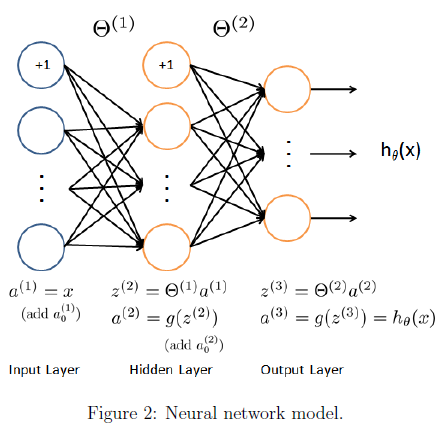

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex3weights.mat` and are loaded into `Theta1` and `Theta2 `by running the code below. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

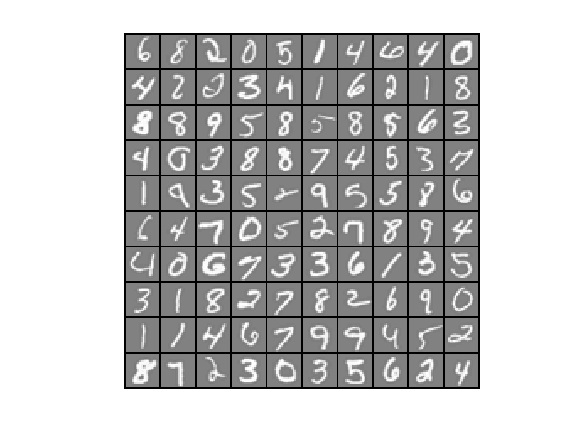

load('ex3data1.mat');

m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

% Load saved matrices from file
load('ex3weights.mat'); 
% Theta1 has size 25 x 401
% Theta2 has size 10 x 26

## 2.2 Feedforward propagation and prediction

Now you will implement feedforward propagation for the neural network. You will need to complete the code in `predict.m` to return the neural network's prediction. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and returns the associated predictions. Similar to the one-vs-all classication strategy, the prediction from the neural network will be the label that has the largest output $(h_\theta(x))_k$.

**Implementation Note: **The matrix `X` contains the examples in rows. When you complete the code in `predict.m`, you will need to add the column of 1's to the matrix. The matrices `Theta1` and `Theta2` contain the parameters for each unit in rows. Specically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. In MATLAB, when you compute $z^{(2)} = \Theta^{(1)}a^{(1)}$, be sure that you index (and if necessary, transpose) `X` correctly so that you get $a^{(1)}$ as a column vector.

Once you are done, run the code below to call your predict function using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the accuracy is about 97.5%.

pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 97.520000


The code below will displaying images from the training set one at a time, while the console prints out the predicted label for the displayed image. Rerun to repeat with another image.

%  Randomly permute examples
rp = randi(m);
% Predict
pred = predict(Theta1, Theta2, X(rp,:));
fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));
% Display 
displayData(X(rp, :));   

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

# Submission and Grading

After completing this assignment, be sure to use the submit function to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

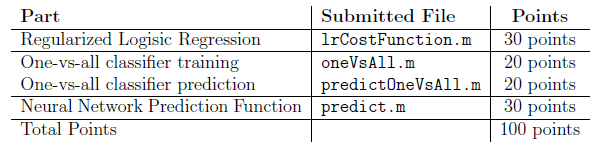

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

**Define the cleanPath function used in the environment setup section:**

Do not modify the code below.

function [] = cleanPath() 
    % cleanPath() obtains the MATLAB search path and removes any other Machine Learning exercise folders. 
    % cleanPath() also prints out the current working directory and the files contained within for reference. 
    pth = strsplit(path,pathsep); % Obtain the search path 
    pth = ([pth{contains(pth,'machine-learning-ex')},{''}]); % Obtain any ML exercise folders that have been added to the path
    rmpath(pth{:}); % Remove these folders from the path
    pwd
    dir
end